# MATLAB y UR5e

Objetivos de estas notas.

- Mover el robot UR5 en Matlab.

- Generar trayectorias simples del robot empleando cinemática directa y cinemática inversa.

Algunos conceptos clave los podrás revisar dentro de la documentación de Matlab en el siguiente [enlace](https://la.mathworks.com/matlabcentral/fileexchange/130124-robotic-manipulators). Mientas que las funciones que usaremos a lo largo de este documento estan documentadas en el [enlace](https://la.mathworks.com/help/robotics/referencelist.html?type=function&s_tid=CRUX_topnav). Recuerda que todas las herramientas que generemos en este espacio nos ayudarán a plantear una solución para nuestro reto en Gazebo.

## Robot UR5e

El UR5e es un robot colaborativo (cobot) de la empresa Universal Robots. Es un robot industrial ligero y versátil, diseñado para aplicaciones de carga media, con un alcance de 850 mm y una capacidad de carga de hasta 5 kg. Es conocido por su facilidad de programación, instalación rápida y flexibilidad para adaptarse a diferentes tareas y entornos de producción. 

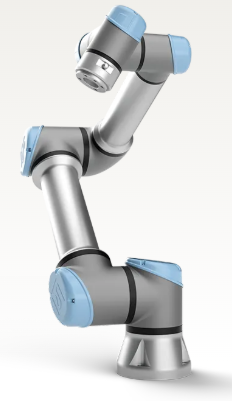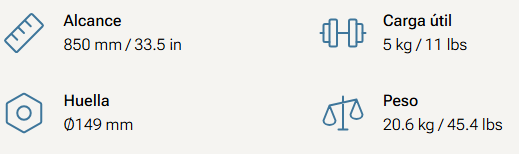

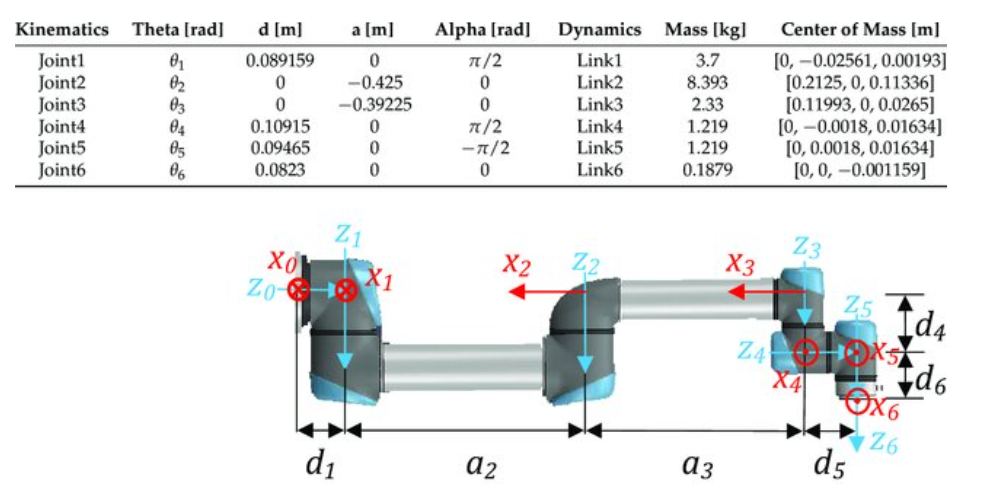

Fig. Robot UR5e con algunas características de operación y tabla DH.

Ejecuta el siguiente código y observa el "gemelo" del robot que tienes en el laboratorio.

% En la siguiente línea de código busca el robot UniversalUR5e que
% estudiaremos en este reto
mi_ur5e = loadrobot("universalUR5e");


%Visualizamos el robot
show(mi_ur5e,"Frames","off");
%Coloca "on" para ver los marcos de referencia

% Observa la información que tiene nuestro modelo
details(mi_ur5e);


  rigidBodyTree handle with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'base_link'  'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}

  Methods, Events, Superclasses



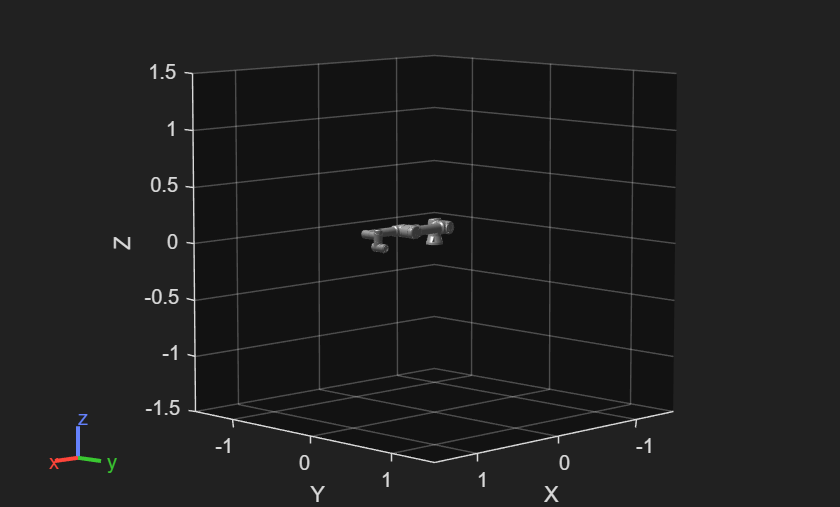

hold off

Rota el cuerpo y observa todos los detalles de tu robot.

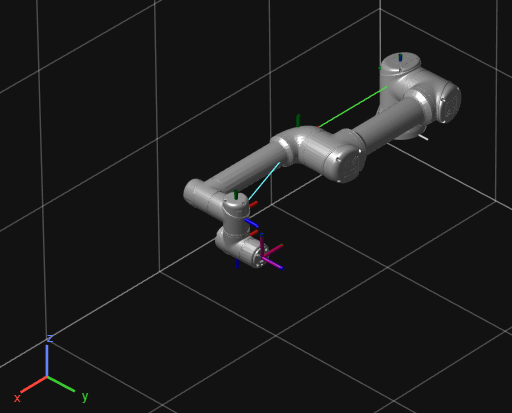

Fig. Robot UR5e en su configuración inicial, diferente a la versión con la que cuentas en el laboratorio.

Revisa los documentos: [https://la.mathworks.com/help/robotics/referencelist.html?type=function&s_tid=CRUX_topnav&category=mobile-robot-modeling](https://la.mathworks.com/help/robotics/referencelist.html?type=function&s_tid=CRUX_topnav&category=mobile-robot-modeling) para que puedas familiarizarte con algunas funciones del modelado de robots móviles

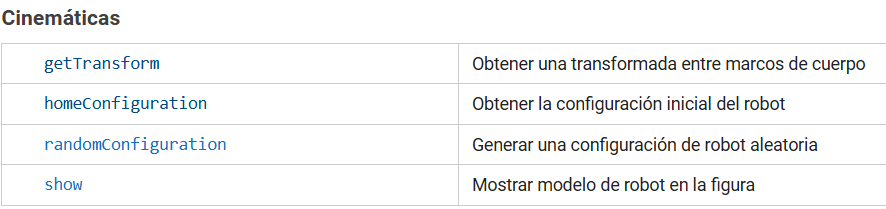

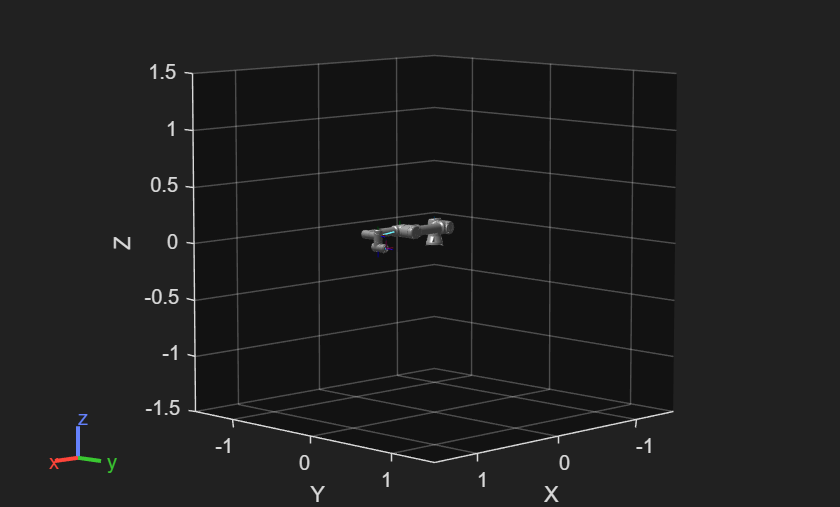

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% Para mostrar el robot
mi_ur5e.show

%show(mi_ur5e)

% Obtenemos la configuración inicial del robot
mi_ur5e.homeConfiguration

ans = 1×6 struct array with fields:
    JointName
    JointPosition


%homeConfiguration(mi_ur5e)

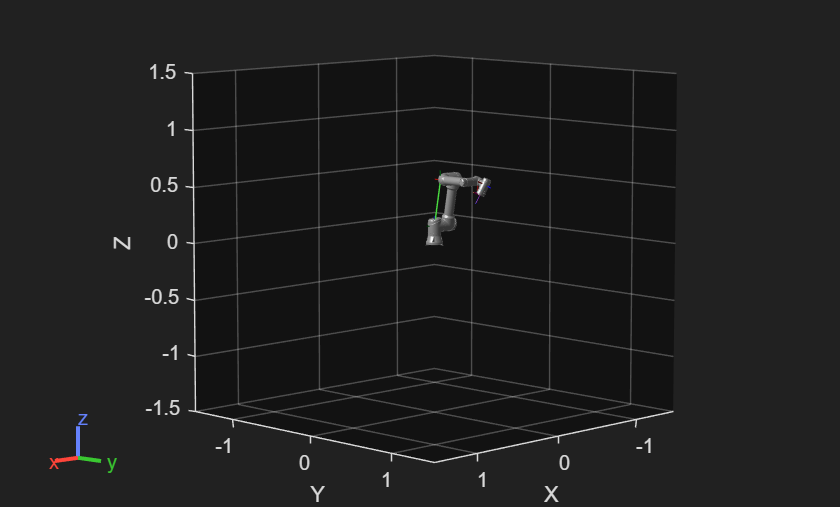

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% Generar una configuración del robot
mi_ur5e.randomConfiguration
randomConfiguration(mi_ur5e);

% Mostramos el robot en una configuración aleatoria
PosicionAleatoria = mi_ur5e.randomConfiguration;

ans =     0.8866   -0.1514   -0.4371    0.3227
    0.2186   -0.6957    0.6842   -0.3315
   -0.4077   -0.7022   -0.5837   -0.6970
         0         0         0    1.0000


mi_ur5e.show(PosicionAleatoria)

ans =     0.8866   -0.1514   -0.4371    0.3227
    0.2186   -0.6957    0.6842   -0.3315
   -0.4077   -0.7022   -0.5837   -0.6970
         0         0         0    1.0000



% PosicionAleatoria = randomConfiguration(mi_ur5e);
% show(mi_ur5e, PosicionAleatoria, "Frames", "off");


  rigidBodyTree handle with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'base_link'  'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}

  Methods, Events, Superclasses



mi_ur5e.getTransform(PosicionAleatoria,"base_link","tool0")

% getTransform(mi_ur5e,PosicionAleatoria,"base_link","tool0")

**Cometario extra: Importancia de las subrutinas**

Recuerda en que Matlab, podemos utilizar "funciones locales" y "funciones globales".

Para simplificar el código, usaremos funciones que podremos llamar dentro de nuestro código


  rigidBodyTree handle with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'base_link'  'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}

  Methods, Events, Superclasses



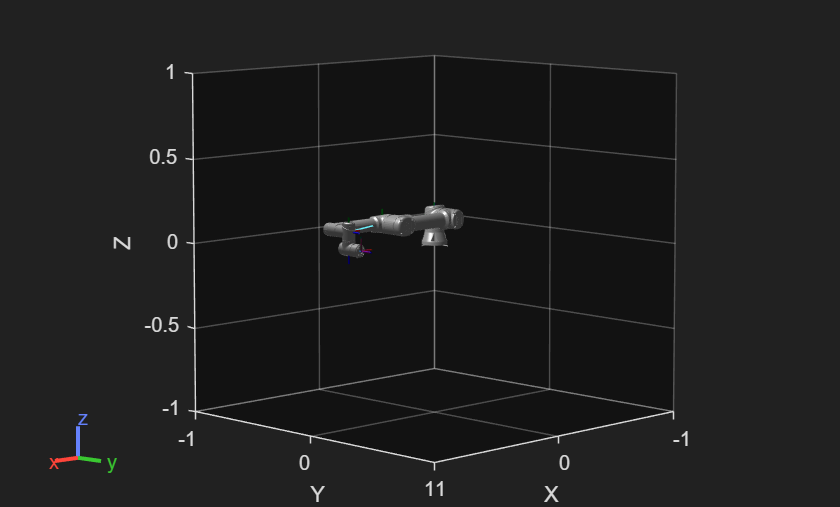

function output = CargarRobot(TipoDeRobot,frames)


  rigidBodyTree handle with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'base_link'  'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}

  Methods, Events, Superclasses



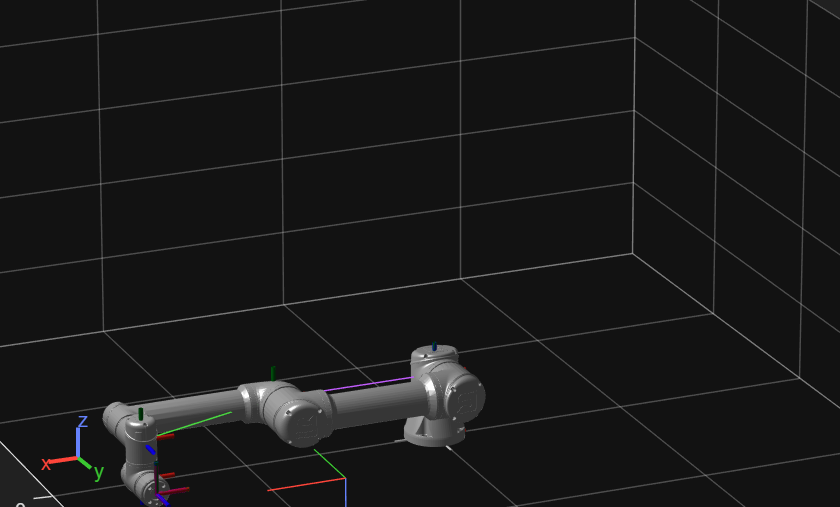

    %Esta función recibe el tipo de robot y si se imprimira con frames o
    %sin frames
    output = loadrobot(TipoDeRobot);
    show(output,"Frames",frames);
    details(output);
    hold off
end


mi_otro_ur5e = CargarRobot('universalUR5e','on');


O funciones que generamos en nuestra carpeta 

mi_otro_otro_ur5e = CargarRobot2('universalUR5e','on');

Los datos que enviaremos al robot son:


### Movimiento individual de articulaciones

En esta sección analizaras en movimeinto del UR5e de forma manual

#### 1. Moviendo las coordenadas articulares

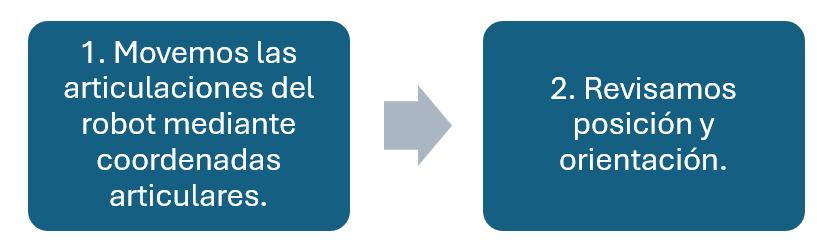

En esta sección veremos como es posible mover individualmente cada una de las articulacones. La información de las articulaciones de nuestro modelo pueden ser leida mediante la función homeConfiguration. 

mi_ur5e = CargarRobot('universalUR5e','on');

ConfiguracionRobot = 1×6 struct array with fields:
    JointName
    JointPosition



ConfiguracionRobot = mi_ur5e.homeConfiguration;
display('Los datos que enviaremos al robot son:');

display(ConfiguracionRobot);

La información de las variables es enviada a 

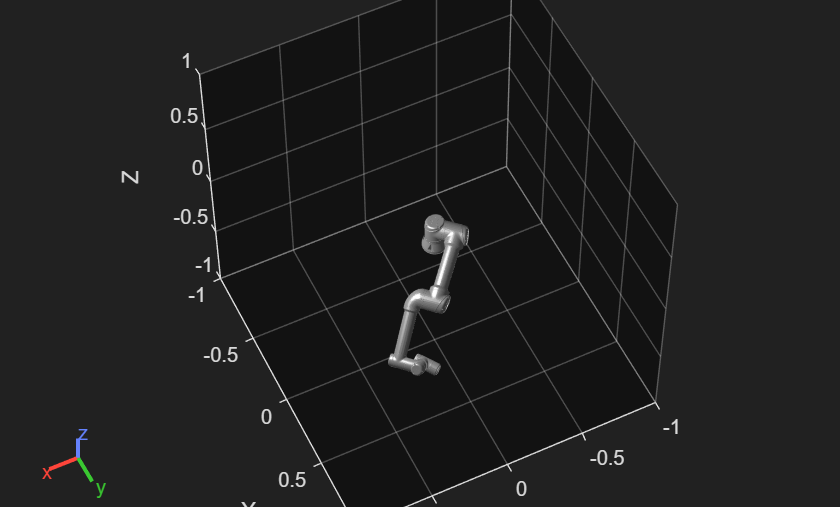

hold off
ConfiguracionRobot(1).JointPosition = 0.8;
ConfiguracionRobot(2).JointPosition = 0.4;
ConfiguracionRobot(3).JointPosition = 0.3;
ConfiguracionRobot(4).JointPosition = 0.2;
ConfiguracionRobot(5).JointPosition = 0.2;
ConfiguracionRobot(6).JointPosition = 0.3;

show(mi_ur5e,ConfiguracionRobot,Frames="off");


view(154,54);
% view(178,22);


#### 2. Calculamos posición y orientación alcanzada

Ttool = getTransform(mi_ur5e,ConfiguracionRobot,"tool0");
fprintf('La transformación a la herramienta es:')

La transformación a la herramienta es:

display(Ttool)

Ttool =    -0.3804    0.6889   -0.6170    0.2702
   -0.1192    0.6251    0.7714    0.6097
    0.9171    0.3670   -0.1556   -0.3331
         0         0         0    1.0000


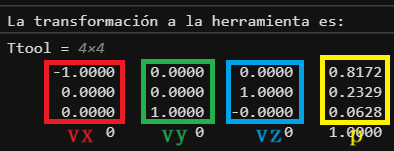

Fig. Representación de la transformación homogénea del robot.

#### 3. Imprimimos punto alcanzado y el vector correspondiente

Usemos funciones o subrutinas para simplificar nuestros códigos.

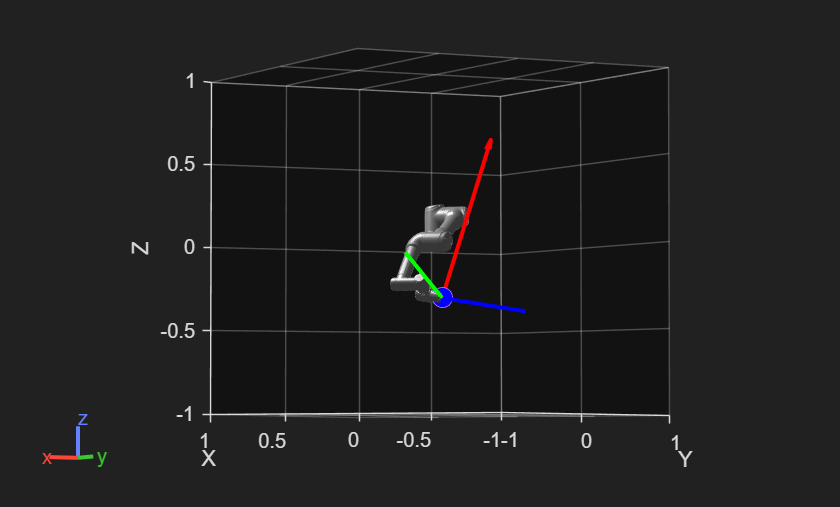

graficar_vectores(Ttool)

#### Actividades sugerida (para alumnos)

- Elimina las secciones de entre las actividades {1,2,3} y modifica las coordenas articulares del robot y ve la ejecución completa de este código.

### Movimiento manual de articulaciones

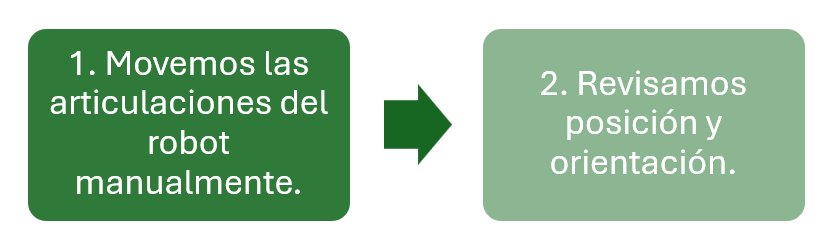

Usaremos una función que nos permitirá interactuar con el robot moviendolo con la mano.

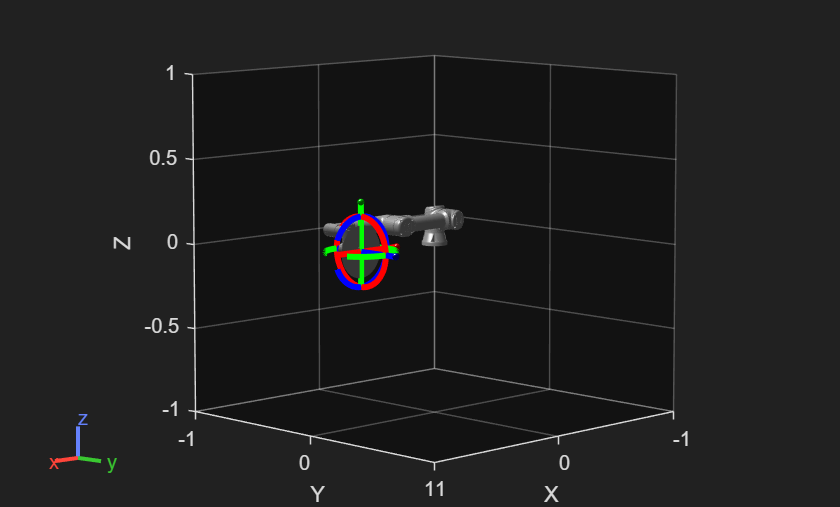

mi_Arbol =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'tool0'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 1
              ShowMarker: 1
           Configuration: [6×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]


mi_Arbol = interactiveRigidBodyTree(mi_ur5e,"Frames","off","MarkerBodyName","tool0")

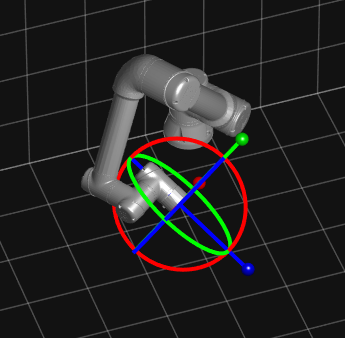

Fig. Podemos mover al robot con el mouse interactuando con los ejes.

Verificamos las ccordenadas articulares y el valor de la pose

mi_Arbol.Configuration

ans =    -0.9666
   -0.8657
    1.9907
    0.5517
    0.5298
   -2.2906


mi_Arbol.MarkerBodyPose

ans =    -0.7331   -0.0207    0.6798    0.3736
    0.4756    0.6989    0.5342   -0.1553
   -0.4862    0.7149   -0.5025    0.0928
         0         0         0    1.0000


Revisa mas propiedades del la función interactiveRigidBodyTree en el enlace:

[https://la.mathworks.com/help/robotics/ref/interactiverigidbodytree.html](https://la.mathworks.com/help/robotics/ref/interactiverigidbodytree.html) 

#### Actividades sugerida (Puedes usar Chat-GPT)

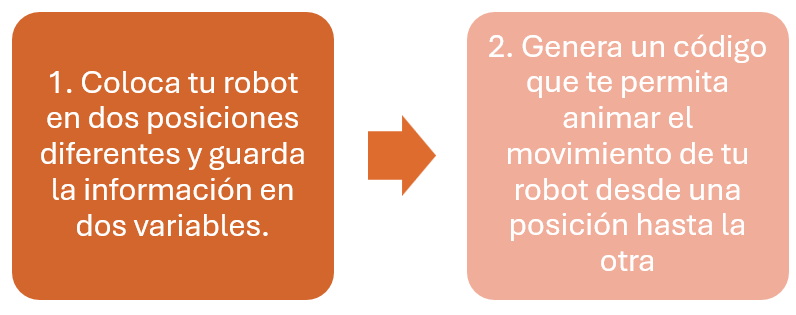

Algunos tips:

- Puedes utilizar las funciones **randomConfiguration o interactiveRigidBodyTree** para encontrar las dos posiciones del robot.

- Para animar la transición de una posición a la otra, puedes construir una interpolación lineal entre las coordenadas articulares.

Solución esperada:

**Paso 1:**

%Determinamos la posiciones
Posicion1=mi_ur5e.randomConfiguration;
Posicion2=mi_ur5e.randomConfiguration;

Paso 2: Utiliza ChatGPT para construir la interpolación lineal, la solución mostrada fue obtenida con el siguiente prompt.

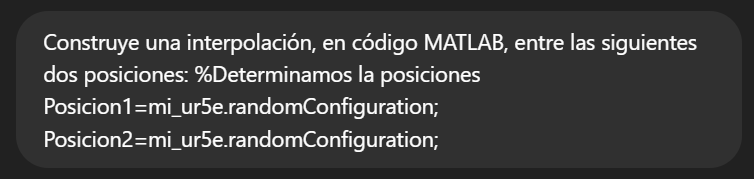

Fig. Prompt de ChatGPT para resolver este reto.

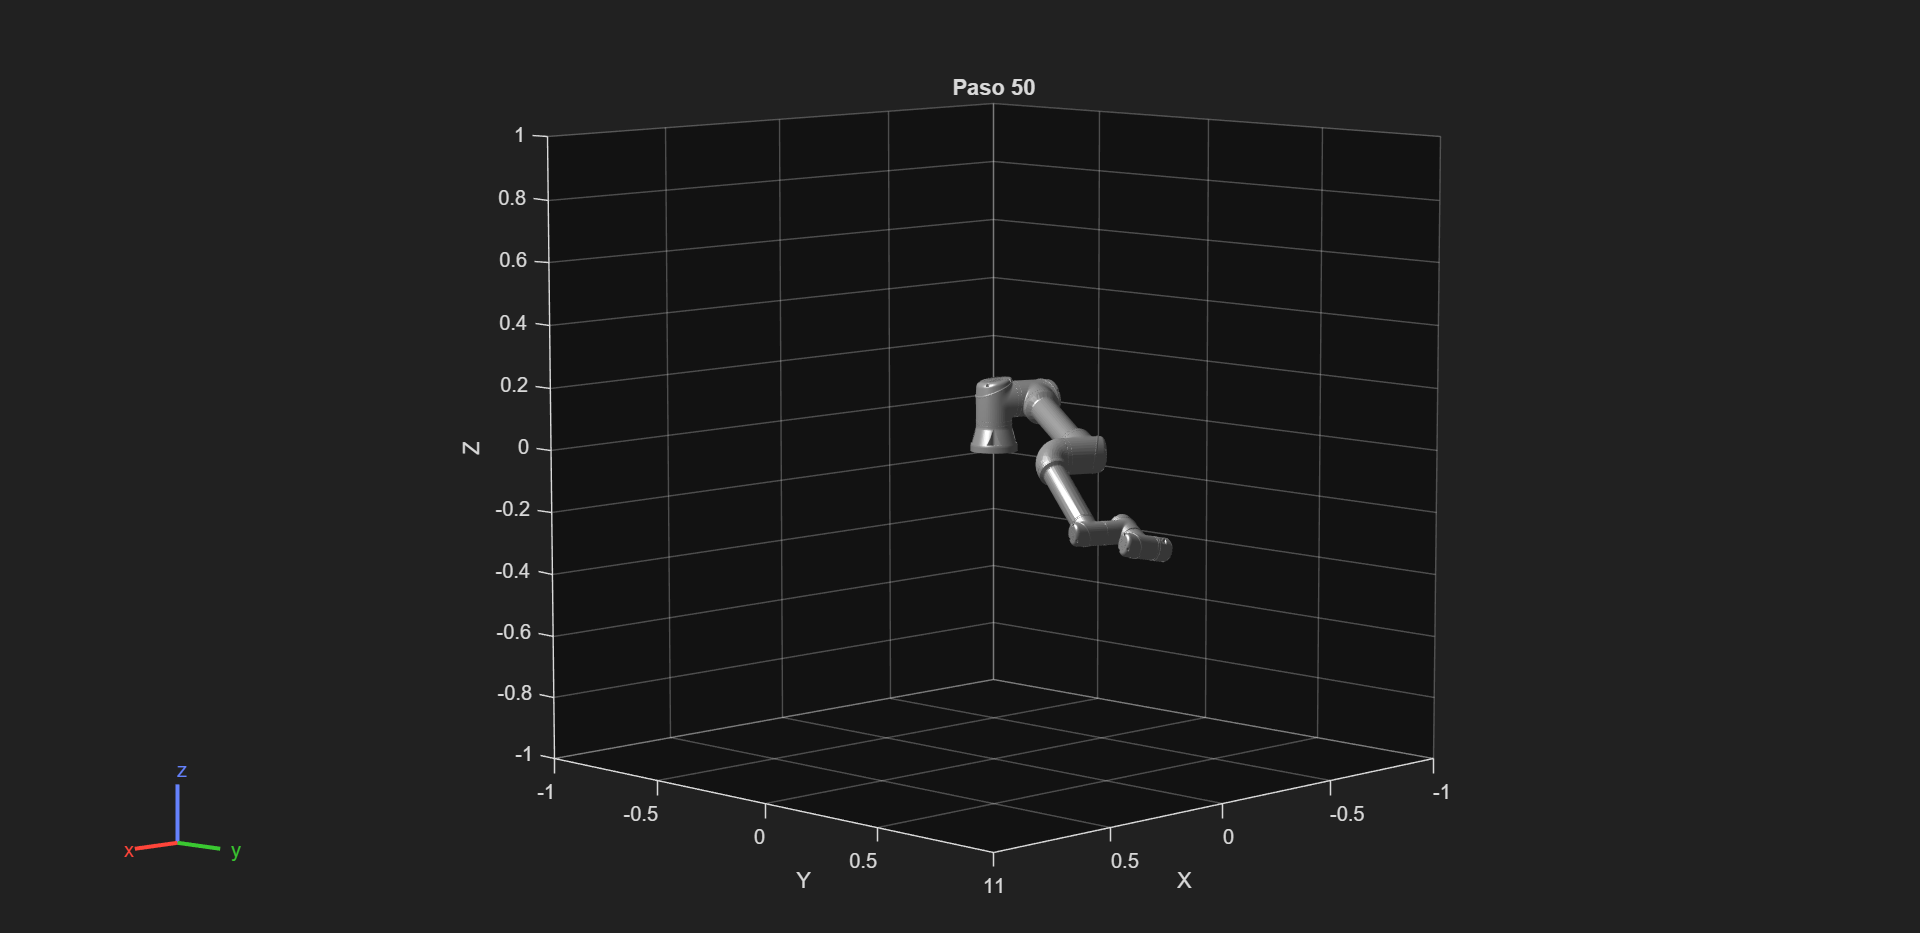

%Solución GPT

% Convertimos las configuraciones a vectores de ángulos articulares
q1 = [Posicion1.JointPosition];
q2 = [Posicion2.JointPosition];

% Número de pasos para la interpolación
N = 50;

% Prealocamos el arreglo para guardar las trayectorias
traj = zeros(N, length(q1));

% Interpolamos línea por línea (espacio articular)
for i = 1:N
    alpha = (i - 1)/(N - 1); % Factor de interpolación de 0 a 1
    traj(i, :) = (1 - alpha) * q1 + alpha * q2;
end

% Visualización de la trayectoria
figure;
for i = 1:N
    config = homeConfiguration(mi_ur5e);
    for j = 1:length(config)
        config(j).JointPosition = traj(i, j);
    end
    show(mi_ur5e, config, 'PreservePlot', false, 'Frames', 'off');
    title(['Paso ', num2str(i)]);
    drawnow;
end

## Área de trabajo

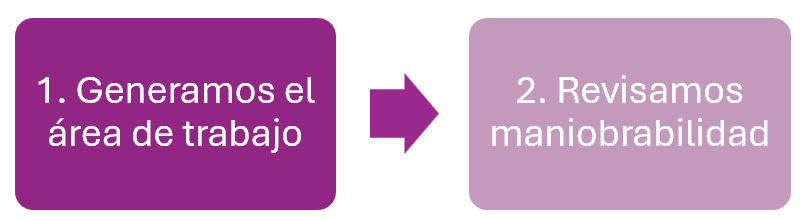

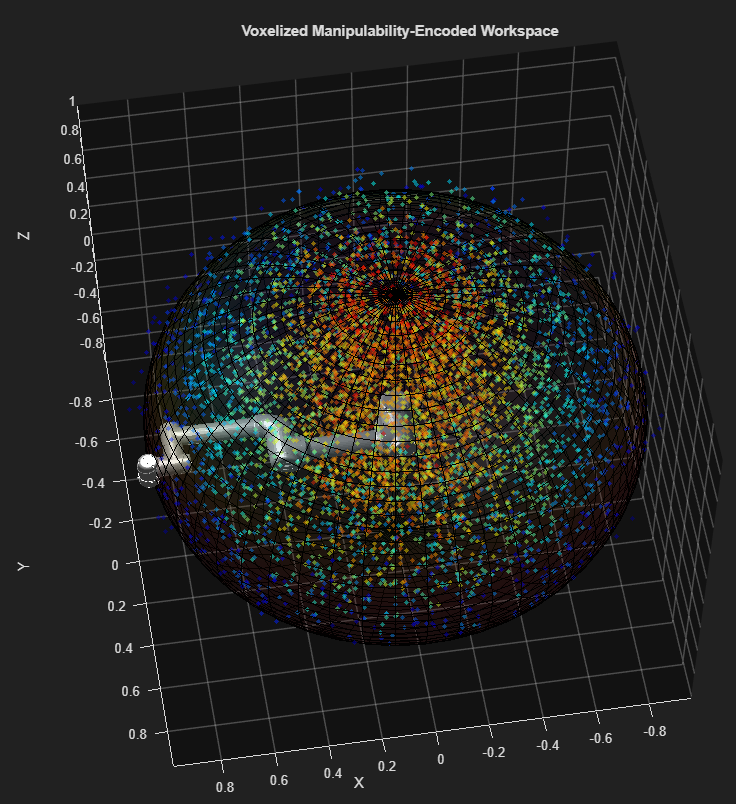

Fig. Área de trabajo de robot UR5e, toda trayectoria deberá estar comprendida en un espacio similar a una esfera.

Cuando estemos trabajando con el robot UR5e, debemos ser conscientes del área del trabajo del robot, con la finalidad de generar trayectorias adecuadas. Matlab nos permite visualizar el área de trabajo del robot para poder restringir los movimientoa una zona donde el robot pueda moverse sin problemas.

% Se generan una serie de puntos en el espacio cartesiano y los
% correspondientes puntos en el espacio articular.
[wksp,cfgs] = generateRobotWorkspace(mi_ur5e,{});
fprintf('Puntos en el espacio de trabajo');

Puntos en el espacio de trabajo

display(wksp);

wksp =     0.2581    0.5736   -0.2455
    0.1184    0.0933   -0.3912
    0.2178    0.0622    0.9900
   -0.2021    0.6229    0.5199
    0.0035   -0.5531    0.0346
   -0.0734    0.4213   -0.0512
    0.1902    0.2716    0.4706
    0.1128    0.2219    0.8933
   -0.1551    0.6431    0.5340
   -0.1796    0.7603    0.2032
    0.2441   -0.0498    0.7530
   -0.2690   -0.1947   -0.3202
    0.5413   -0.1393    0.8984
   -0.0352   -0.4577    0.6666
    0.8158   -0.4817    0.2495


fprintf('Puntos en el espacio articular');

Puntos en el espacio articular

display(cfgs);

cfgs =    -1.6585   -3.0002   -1.4824    5.8484    0.7394   -0.9454
    5.3810    2.2367   -1.1824   -4.4564   -1.3945   -2.7401
   -1.7125    4.3975    0.1236   -5.8238   -5.5431   -1.0685
    5.1650    4.4148   -1.3489    5.3782    2.0132    4.7606
   -1.9766    5.8733    1.3724   -5.8827   -0.4817   -5.6768
   -5.0790    5.5516    2.2632    3.9645    5.7594   -5.0556
    0.5895   -1.4119    1.6519   -4.3027   -4.5790    2.8350
   -5.9708    5.5719   -0.9298   -3.3228   -1.1217   -4.6975
    1.4749    5.2089    1.3502    2.7664   -0.5920    0.2417
   -1.0795   -3.7295    1.3728    3.2853   -0.8322   -3.9078
    5.6296   -1.4924    0.7697    2.3326    1.8188   -6.2380
   -3.1660   -6.0580    2.0161   -2.4708    0.8200   -0.2151
    5.7147   -0.6957   -0.6185    6.0919    1.1493    0.7173
   -1.8620    4.9394    0.7391   -5.1515   -4.3470   -1.3807
   -0.7470    6.0441    0.2075    4.3225   -0.8254    4.6208


% Elsiguiente indice te permite conocer la maniobrabilidad del robot en
% algún tipo de dirección

mIdx = manipulabilityIndex(mi_ur5e,cfgs,MotionComponent=[0 0 0 0 0 1]); %[rx ry rz x y z]
show(mi_ur5e,ConfiguracionRobot,"Frames","off");
fprintf('Indice de maniobrabilidad');

Indice de maniobrabilidad

display(mIdx)

mIdx =     0.6286
    0.2717
    0.1676
    0.8451
    0.5381
    0.3772
    0.4165
    0.2610
    0.7562
    0.8657
    0.3129
    0.3183
    0.5805
    0.5718
    1.0671


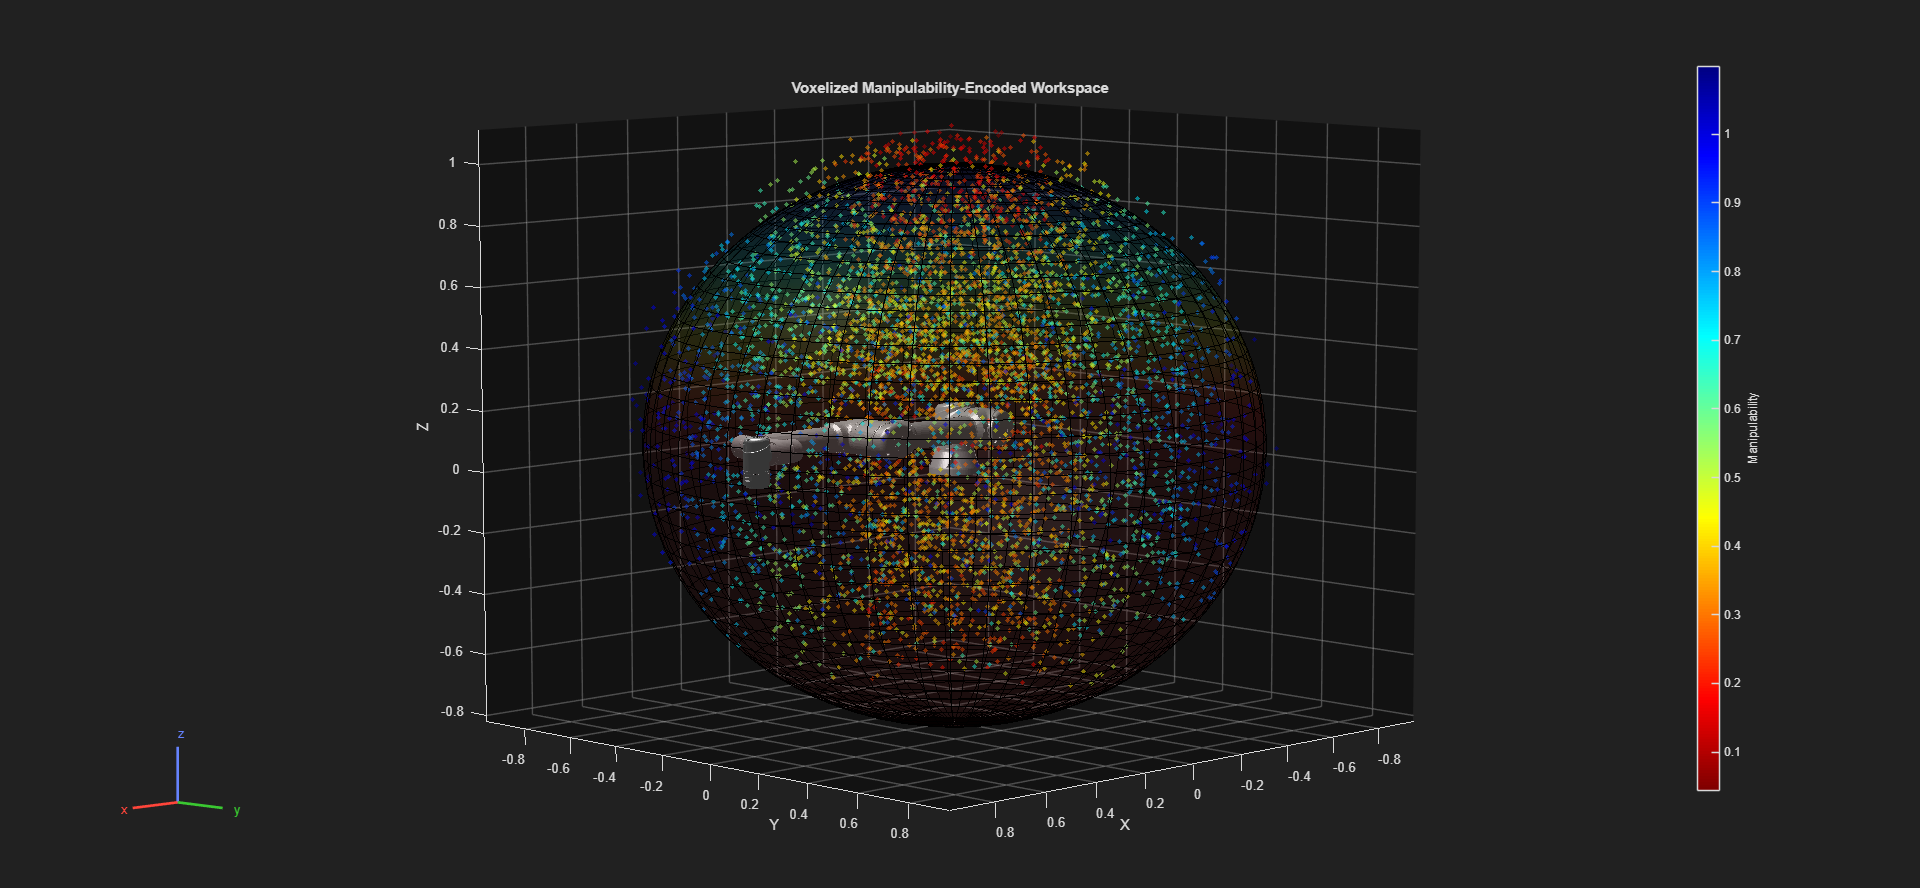

ans =   Axes (Primary) with properties:

             XLim: [-0.8836 0.9164]
             YLim: [-0.8593 0.9407]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1242 0.1100 0.7406 0.8150]
            Units: 'normalized'

  Show all properties


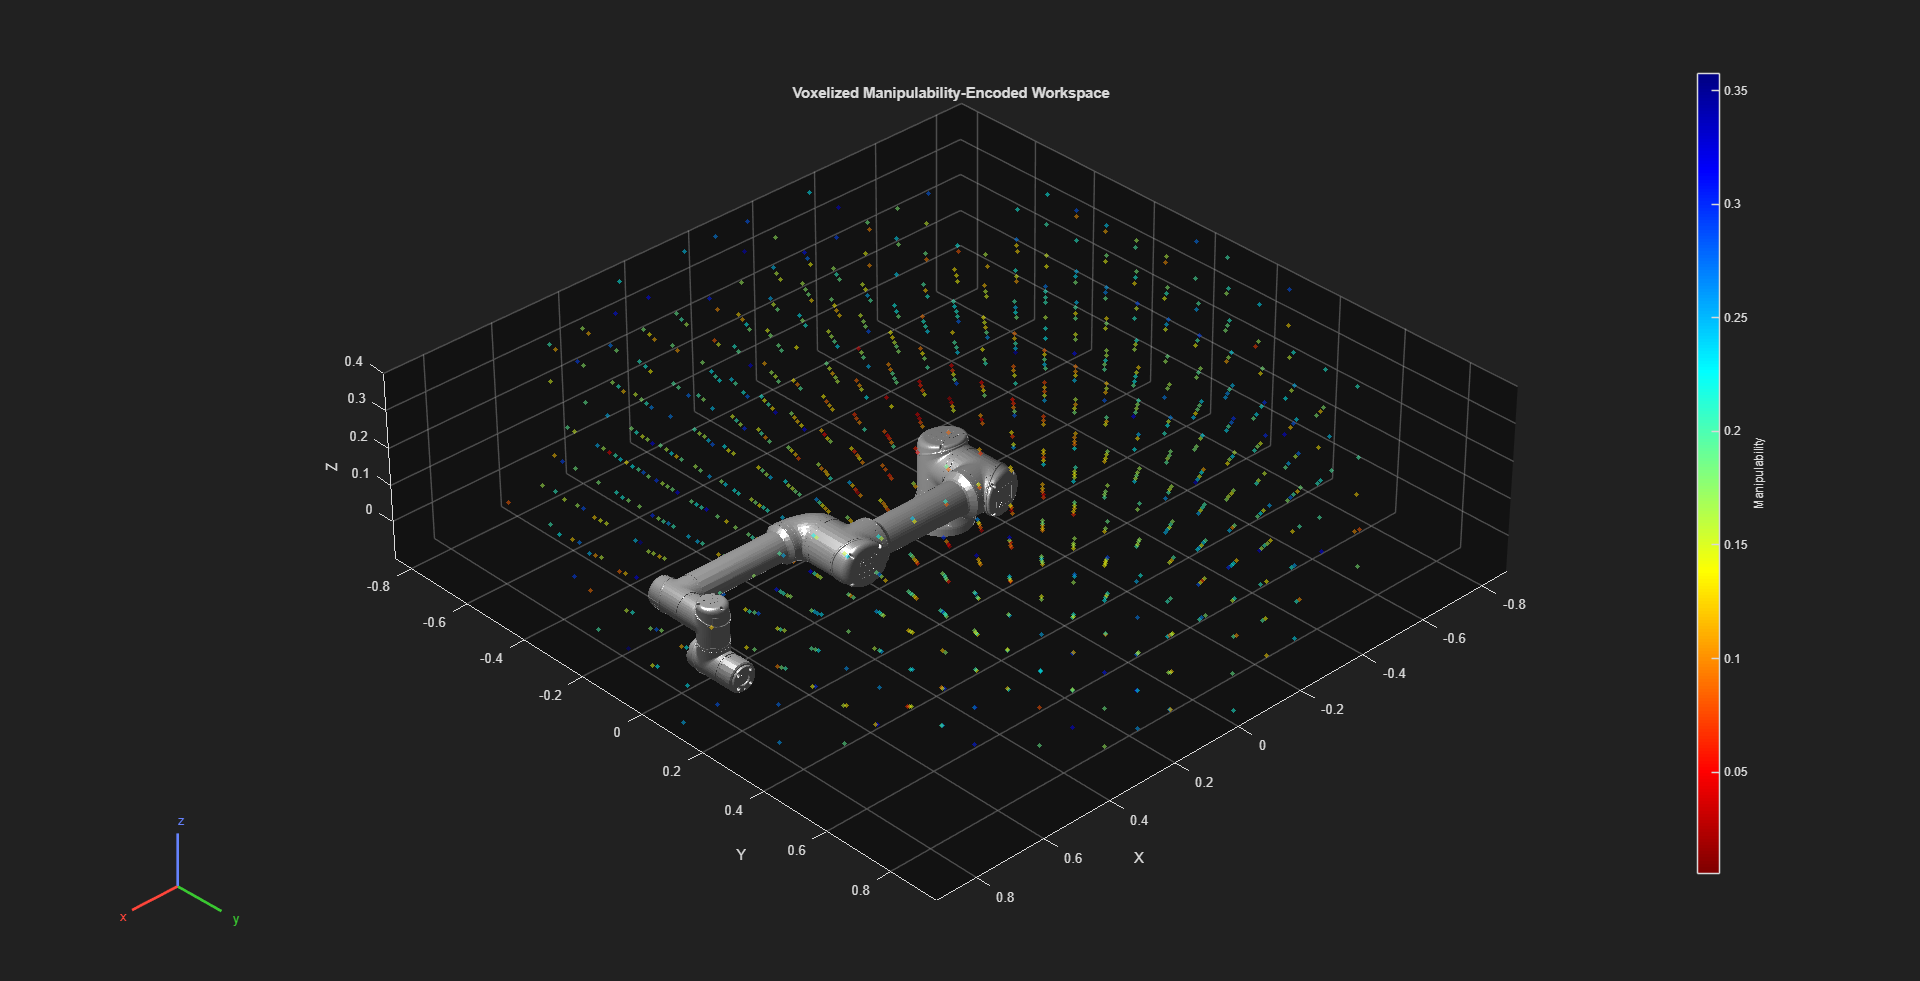


%Representación gráfica del índice de maniobrabilidad
hold on

showWorkspaceAnalysis(wksp,mIdx,Voxelize=false)
axis auto
title("Voxelized Manipulability-Encoded Workspace")

% Graficamos el área de trabajo tentativa
graficarEsferaHueca(0.9119)
hold off

## ¿Mejorando la representación gráfica? Añadiendo gripper

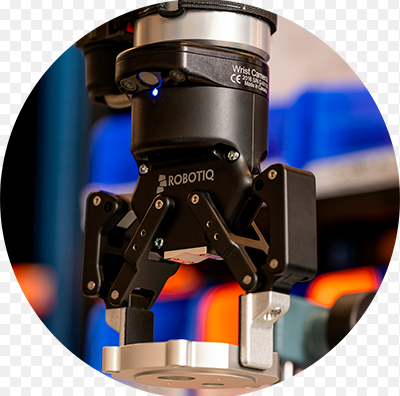

Fig. Gripper con cámara

Aunque añadir el gripper a nuestra simulación puede aportar visibilidad al gripper, no hemos podido incorporar su análisis de forma eficienteo por el número y configuración de eslabones con los que esta construido el modelo.

%Cargamos gripper
mi_gripper = loadrobot('robotiq2F85');
%Agregamos gripper al final de la herramienta
addSubtree(mi_ur5e, 'tool0', mi_gripper, ReplaceBase=false);

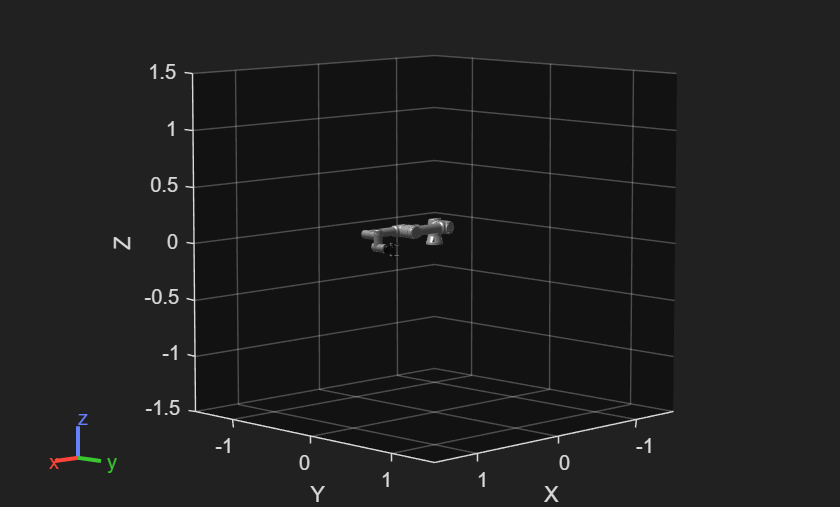

show(mi_ur5e,"Frames","off");

ConfiguracionRobot = mi_ur5e.homeConfiguration;
fprintf('La nueva configuración del robot será');

La nueva configuración del robot será

display(ConfiguracionRobot)

ConfiguracionRobot = 1×12 struct array with fields:
    JointName
    JointPosition


Abrimos y cerramos el gripper

valorGripper = 0;
for n = 7:12
    if  or(n==8,n==12)
        Signo = -1;
    else
        Signo = 1;
    end
    ConfiguracionRobot(n).JointPosition = Signo*valorGripper;
end
show(mi_ur5e,ConfiguracionRobot,Frames="off")

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


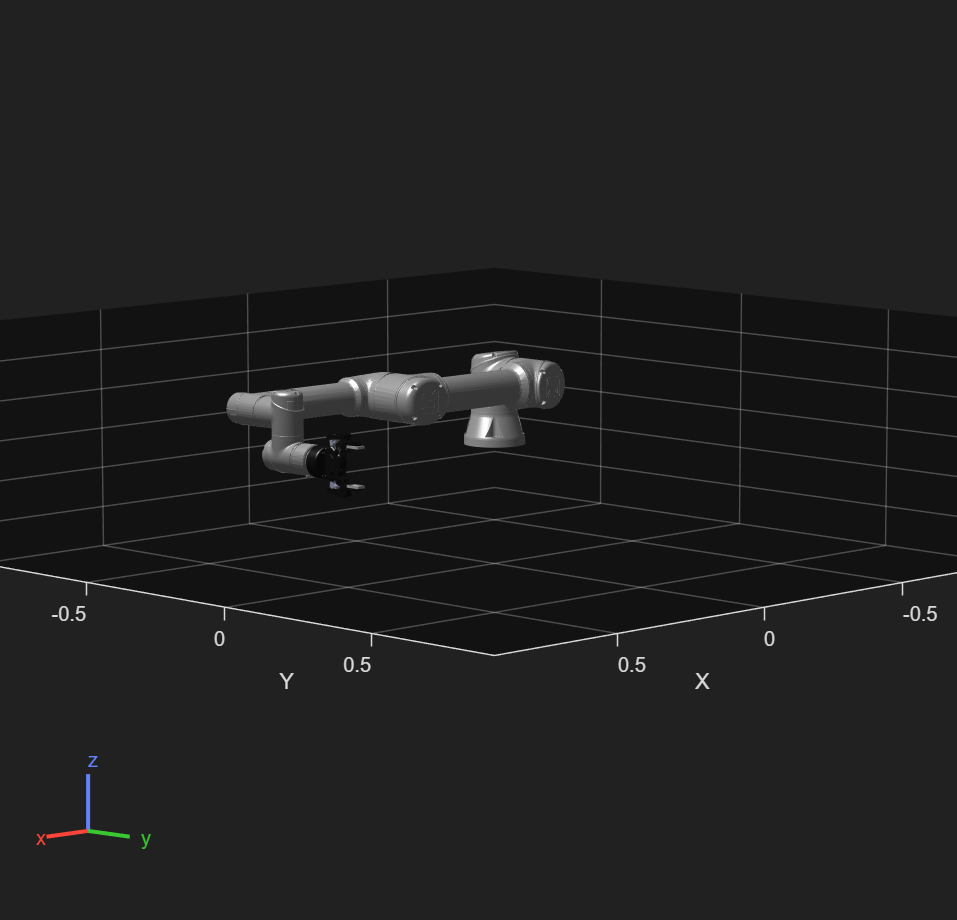

xlim([-0.9,0.9])
ylim([-0.9,0.9])
zlim([-0.3,0.3])

#### Actividades sugerida (para alumnos): Pick-and-place

- Crea un código "Pick-and-place", para mover el robot entre dos puntos con las siguientes coordenadas articulares.

$q_0 =\left\lbrack \begin{array}{c}
0\\
-0\ldotp 7854\\
1\ldotp 57\\
-2\ldotp 35\\
-1\ldotp 57\\
0
\end{array}\right\rbrack$, y $q_f =\left\lbrack \begin{array}{c}
1\ldotp 57\\
0\ldotp 7854\\
-1\ldotp 57\\
-0\ldotp 7854\\
-1\ldotp 57\\
0
\end{array}\right\rbrack$

En la primer posición se cierra el gripper, en la otra, se abre el gripper.

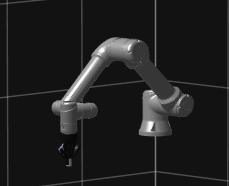------->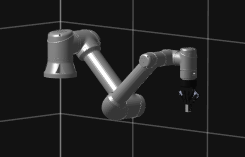

Fig. Realice una rutina de un robot moviendose entre dos posiciones

### Diagrama de flujo.

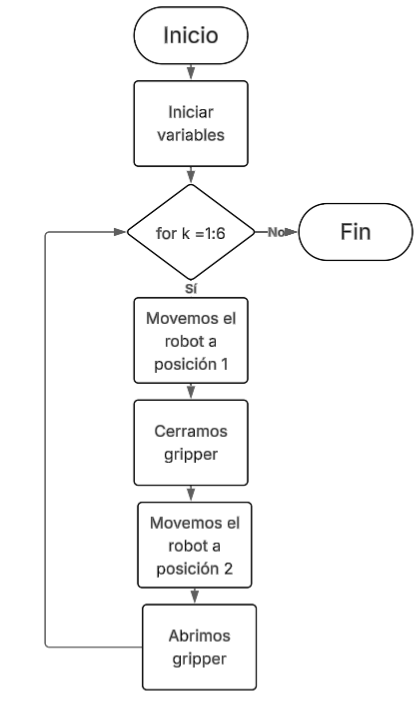

Fig. Estrategia parcial para la rutina pick-and-place

%Solución 1

%%Iniciamos variables
%Borramos variables, ¡por si las dudas!
clear all

%Declaramos el robot con gripper y el como enviamos información al robot
mi_ur5e = loadrobot("universalUR5e");
mi_gripper = loadrobot('robotiq2F85');
addSubtree(mi_ur5e, 'tool0', mi_gripper, ReplaceBase=false);
ConfiguracionRobot = mi_ur5e.homeConfiguration;
fprintf('La nueva configuración del robot será');

La nueva configuración del robot será

display(ConfiguracionRobot)

ConfiguracionRobot = 1×12 struct array with fields:
    JointName
    JointPosition


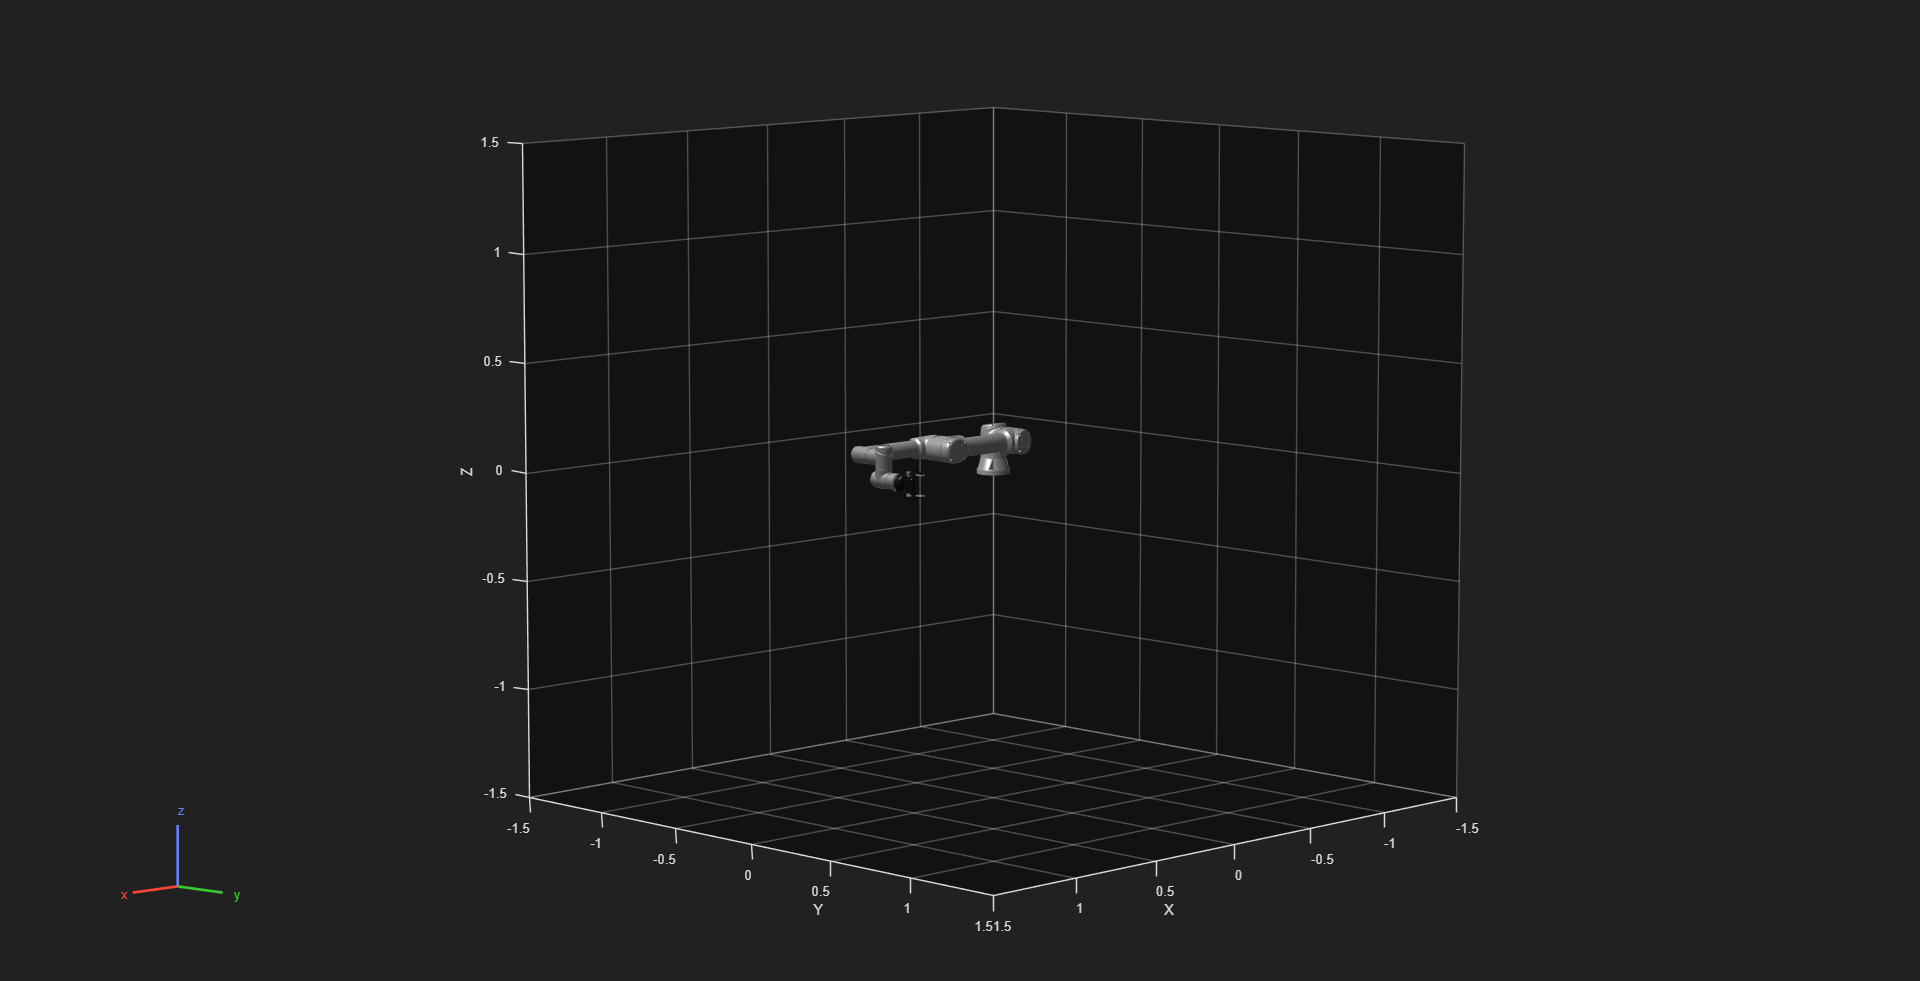


%Mostramos el robot
show(mi_ur5e,"Frames","off");

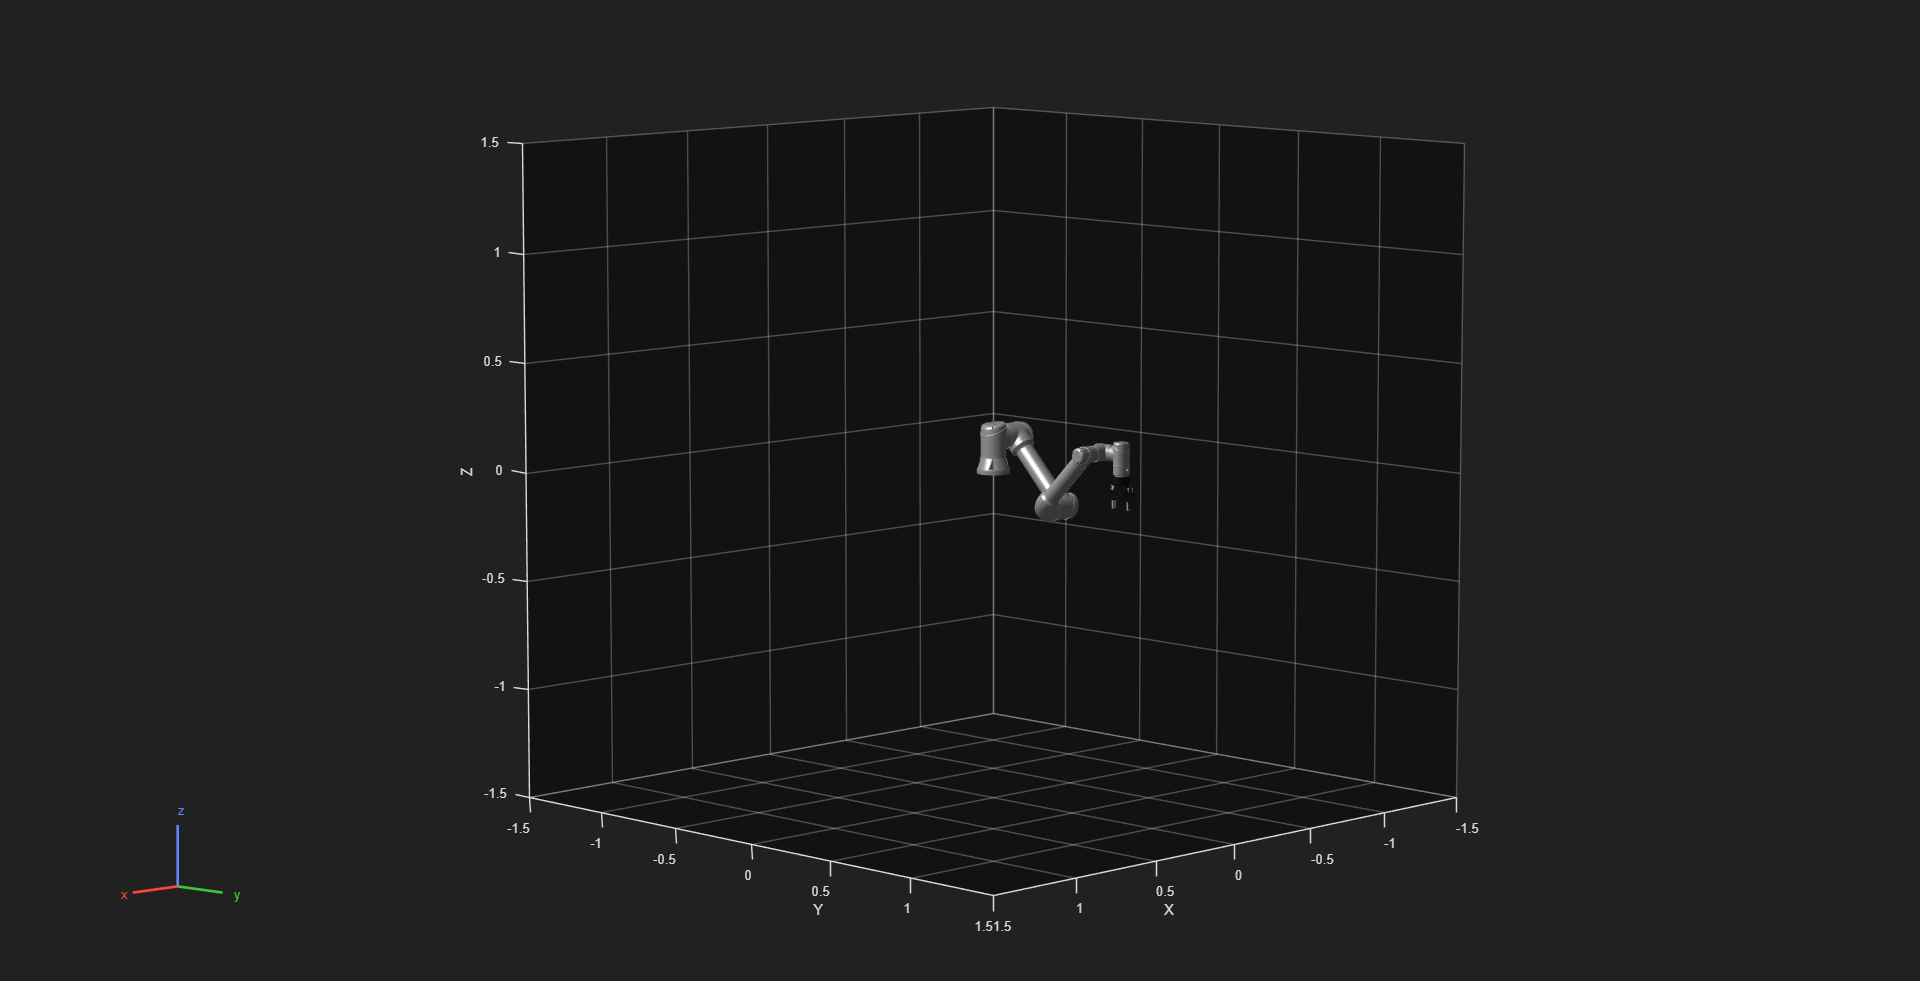


%Condiciones iniciales
PuntoA = [0;-0.7854;1.57;-2.35;-1.57;0];
PuntoB = [1.57;0.7854;-1.57;-0.7854;-1.57;0];

for k=1:6
    ConfiguracionRobot = moverRobot(ConfiguracionRobot,PuntoA,mi_ur5e);
    pause(3);
    ConfiguracionRobot = cerramosGripper(ConfiguracionRobot,mi_ur5e);
    pause(3);
    ConfiguracionRobot = moverRobot(ConfiguracionRobot,PuntoB,mi_ur5e);
    pause(3);
    ConfiguracionRobot = abrimosGripper(ConfiguracionRobot,mi_ur5e);
    pause(3);
end



function ConfiguracionRobot = moverRobot(ConfiguracionRobot,Punto,mi_ur5e)
    for n=1:6
        ConfiguracionRobot(n).JointPosition = Punto(n);
    end
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end

function ConfiguracionRobot = cerramosGripper(ConfiguracionRobot,mi_ur5e)
    valorGripper = 0.8;
    for n = 7:12
        if  or(n==8,n==12)
            Signo = -1;
        else
            Signo = 1;
        end
        ConfiguracionRobot(n).JointPosition = Signo*valorGripper;
    end
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end

function ConfiguracionRobot = abrimosGripper(ConfiguracionRobot,mi_ur5e)
    valorGripper = 0.0;
    for n = 7:12
        if  or(n==8,n==12)
            Signo = -1;
        else
            Signo = 1;
        end
        ConfiguracionRobot(n).JointPosition = Signo*valorGripper;
    end
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end


2. Modifica el código para que la función "cerramosGripper" y "abrimosGripper" sean ejecutadas por una sola función. Define una nueva variable que te ayude a ajustar el porcentaje de apertura del gripper.

3. Esta trayectoria tiene un problema, solo se ha configurado la posición inicial y final. Modifica tu código para que tu simulación del robot pase por algunos puntos intermedios entre la posición final e inicial

%Solución 2
for k=1:3
    for t = 0:0.1:1
        ConfiguracionRobot = moverRobot(PuntoB*(1-t)+PuntoA*t,ConfiguracionRobot,mi_ur5e);
        pause(0.01);
    end
    pause(3);
    ConfiguracionRobot = cerramosGripper(ConfiguracionRobot,mi_ur5e);
    pause(3);
    for t =0:0.1:1
        ConfiguracionRobot = moverRobot(PuntoB*t+PuntoA*(1-t),ConfiguracionRobot,mi_ur5e);
        pause(0.01);
    end
    pause(3);
    ConfiguracionRobot = abrimosGripper(ConfiguracionRobot,mi_ur5e);
    pause(3);
end

## Cinemática inversa por medio de MATLAB

Considere que queremos alcanzar el punto, relativo a la base del robot,


$$p_{\textrm{robot}} =\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 4\\
0\ldotp 1
\end{array}\right\rbrack$$


Con una orientación del gripper


$$R=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$$


Lo que nos conduce a la transformación homogénea


$$T=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\ldotp 4\\
0 & -1 & 0 & 0\ldotp 4\\
0 & 0 & -1 & 0\ldotp 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


¿Que valores articulares requerimos? Apliquemos las estrategiasde cinemática inversa que tiene precargadas MATLAB. Así como la que utilizamos nosotros.


  rigidBodyTree handle with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'base_link'  'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}

  Methods, Events, Superclasses



clear all
mi_ur5e = CargarRobot('universalUR5e','off');

ConfiguracionRobot = homeConfiguration(mi_ur5e);


show(mi_ur5e,ConfiguracionRobot,PreservePlot=false,Frames="off");

axis([-1 1 -1 1 0 1])
title("UR5e Home Configuration")
angles = [0 0 -pi];
trvec = [0.4 0.4 0.1];

poseTF = se3(angles,"eul","ZYX",trvec)

poseTF = se3
    1.0000         0         0    0.4000
         0   -1.0000    0.0000    0.4000
         0   -0.0000   -1.0000    0.1000
         0         0         0    1.0000


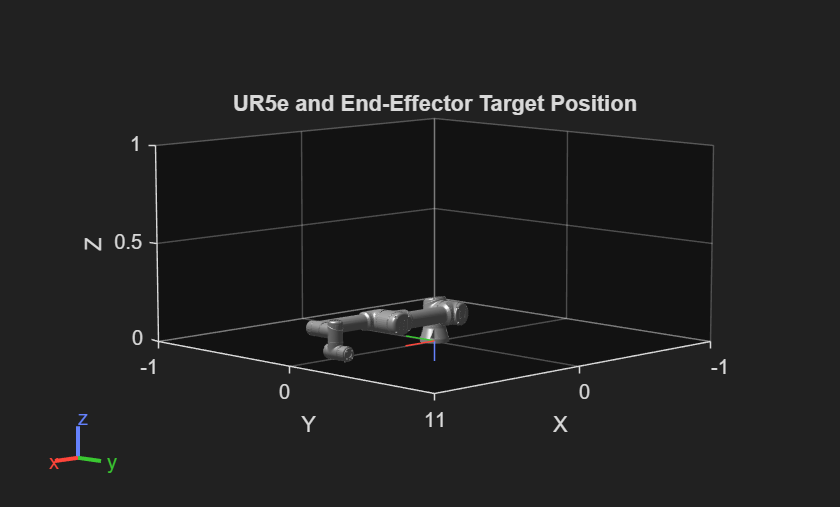


hold on
plotTransforms(poseTF,FrameSize=0.2);
title("UR5e and End-Effector Target Position")

Resolvemos la cinemática inversa empleando los recursos de MATLAB

ik = inverseKinematics("RigidBodyTree",mi_ur5e);
weights = [1 1 1 1 1 1];

%Prueba weights = [1 1 1 10 1 1];
initialguess = homeConfiguration(mi_ur5e);
[configSoln,solnInfo] = ik("tool0",poseTF.tform,weights,initialguess);
display(configSoln)

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


display(solnInfo)

solnInfo = struct with fields:
           Iterations: 216
    NumRandomRestarts: 8
        PoseErrorNorm: 7.0127e-09
             ExitFlag: 1
               Status: 'success'


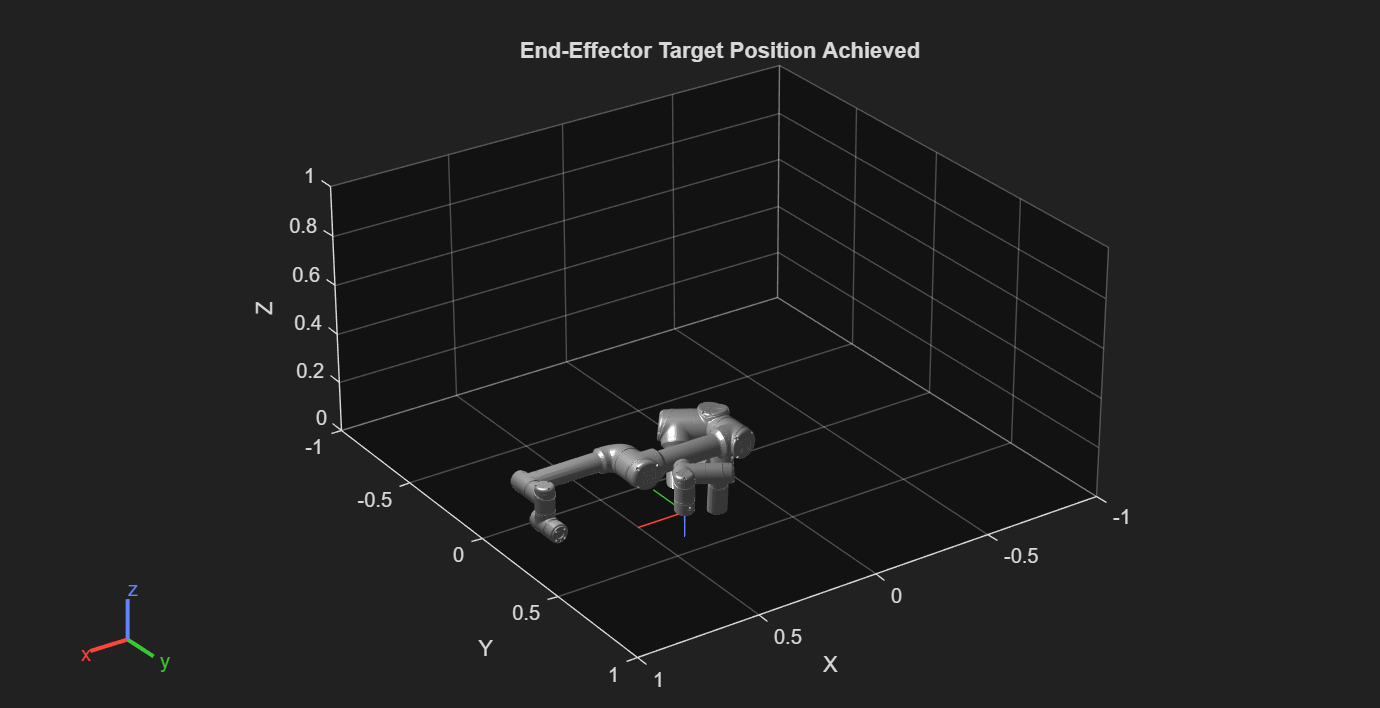

show(mi_ur5e,configSoln,PreservePlot=true,Frames="off");
title("End-Effector Target Position Achieved")

Repetimos el experimento asumiendo un desplazamiento lineal en el eje x.

angles2 = [0 0 -pi];
trvec2 = [-0.4 0.4 0.1];

poseTF2 = se3(angles2,"eul","ZYX",trvec2)

poseTF2 = se3
    1.0000         0         0   -0.4000
         0   -1.0000    0.0000    0.4000
         0   -0.0000   -1.0000    0.1000
         0         0         0    1.0000


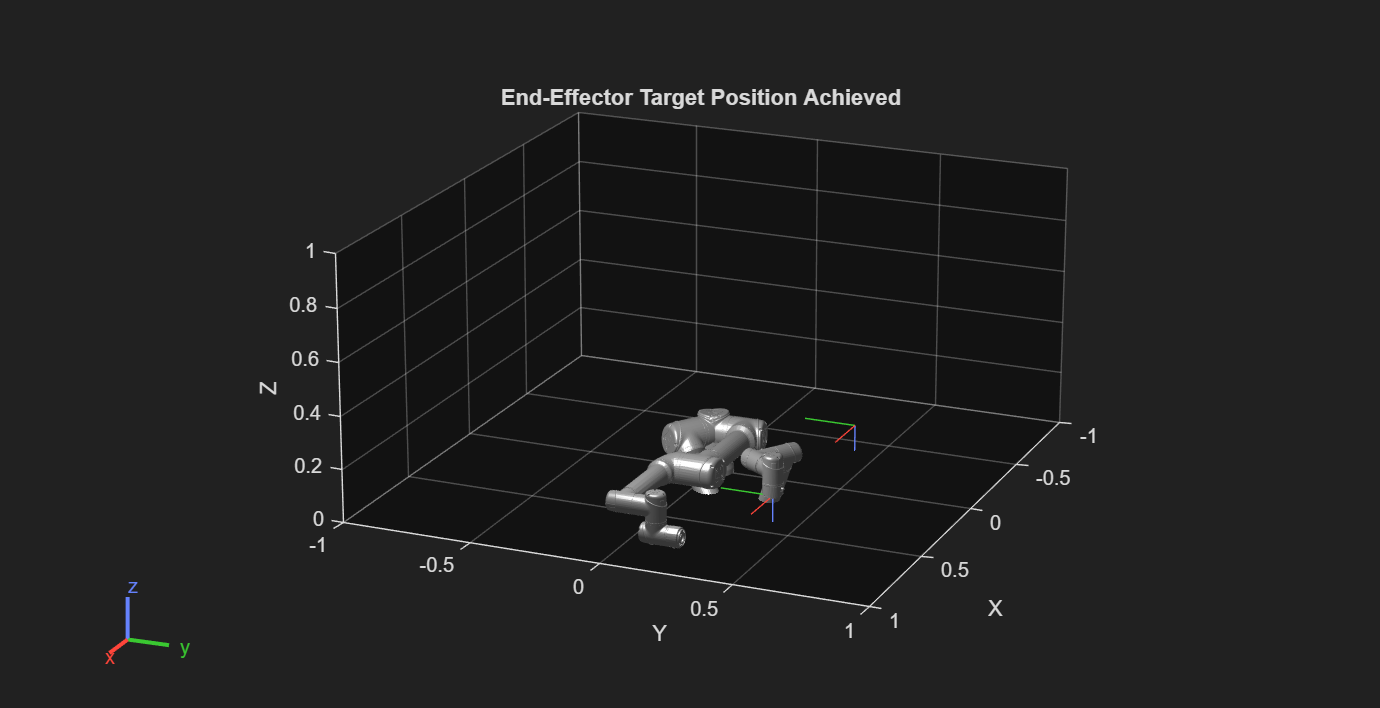


hold on
plotTransforms(poseTF2,FrameSize=0.2);

Resolvemos la cinemática inversa empleando los recursos de MATLAB

ik = inverseKinematics("RigidBodyTree",mi_ur5e);
weights = [1 1 1 1 1 1];

initialguess = configSoln;
[configSoln2,solnInfo2] = ik("tool0",poseTF2.tform,weights,initialguess);
display(configSoln2)

configSoln2 = 1×6 struct array with fields:
    JointName
    JointPosition


display(solnInfo2)

solnInfo2 = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1473e-08
             ExitFlag: 1
               Status: 'success'


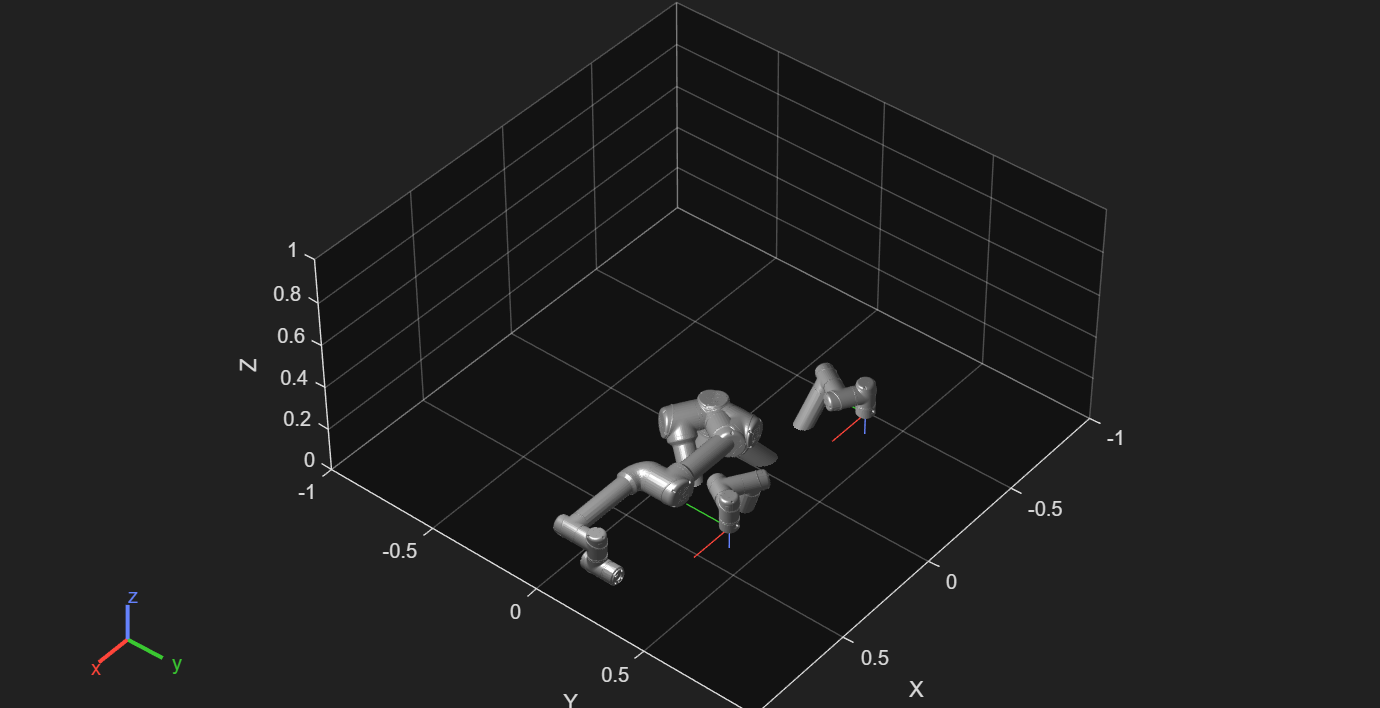

show(mi_ur5e,configSoln2,PreservePlot=true,Frames="off");
title("End-Effector Target Position Achieved")

Realizamos el movimiento lineal entre el punto inicial y punto final

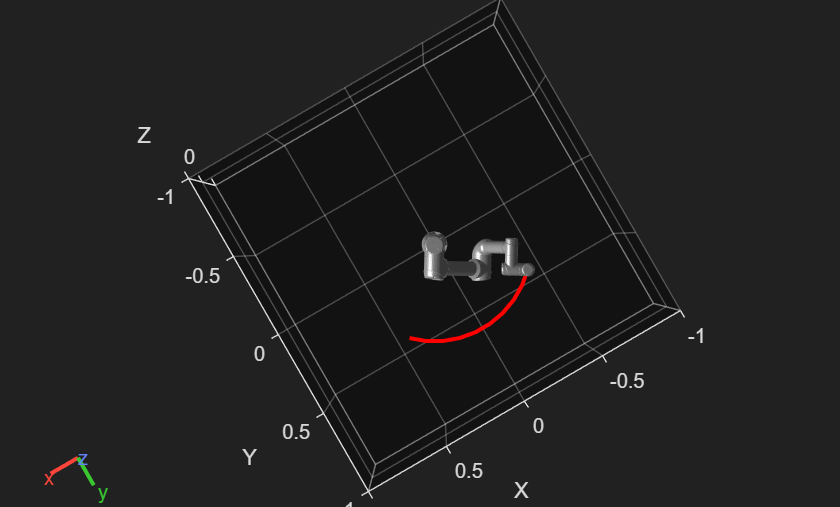

movimientoLineal(mi_ur5e,configSoln,configSoln2,10)

%% Mostrar videos en presentación de inconvenientes de uso de inverseKinematics


### Cinemática inversa empleando solución exacta

En esta sección observaremos las 8 posibles configuraciones con las que se puede alcanzar la configuración del robot

angles = [0 0 -pi];
trvec = [0.4 0 0.1];

poseTF = se3(angles,"eul","ZYX",trvec)

poseTF = se3
    1.0000         0         0    0.4000
         0   -1.0000    0.0000         0
         0   -0.0000   -1.0000    0.1000
         0         0         0    1.0000



CinematicaInversa = TodasPosiblesSolucionesUR5e(poseTF.tform);

q = CinematicaInversa.Angulos

q =     2.8018    2.8018    2.8018    2.8018    0.3397    0.3397    0.3397    0.3397
    0.4406   -1.2345    0.4291   -1.6779   -1.4637    2.7124   -1.9071    2.7010
   -1.7735    1.7735   -2.2816    2.2816   -2.2816    2.2816   -1.7735    1.7735
    2.9037    1.0318    0.2817   -2.1745   -0.9670    2.8599    2.1098    0.2379
    1.5708    1.5708   -1.5708   -1.5708    1.5708    1.5708   -1.5708   -1.5708
    1.2310    1.2310   -1.9105   -1.9105   -1.2310   -1.2310    1.9105    1.9105


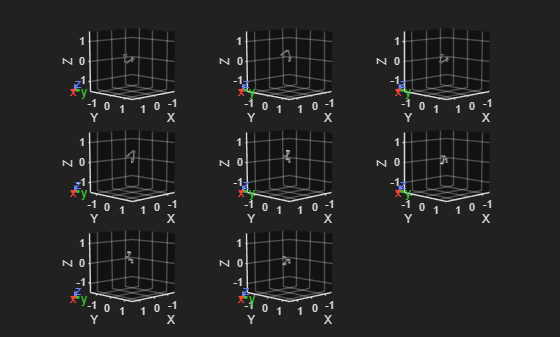

q(1,:)=q(1,:)+pi; %Correción de parámetros.

for m = 1:8
    for k = 1:6
        ConfiguracionRobot(k).JointPosition = q(k,m);
    end
    subplot(3,3,m)
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end

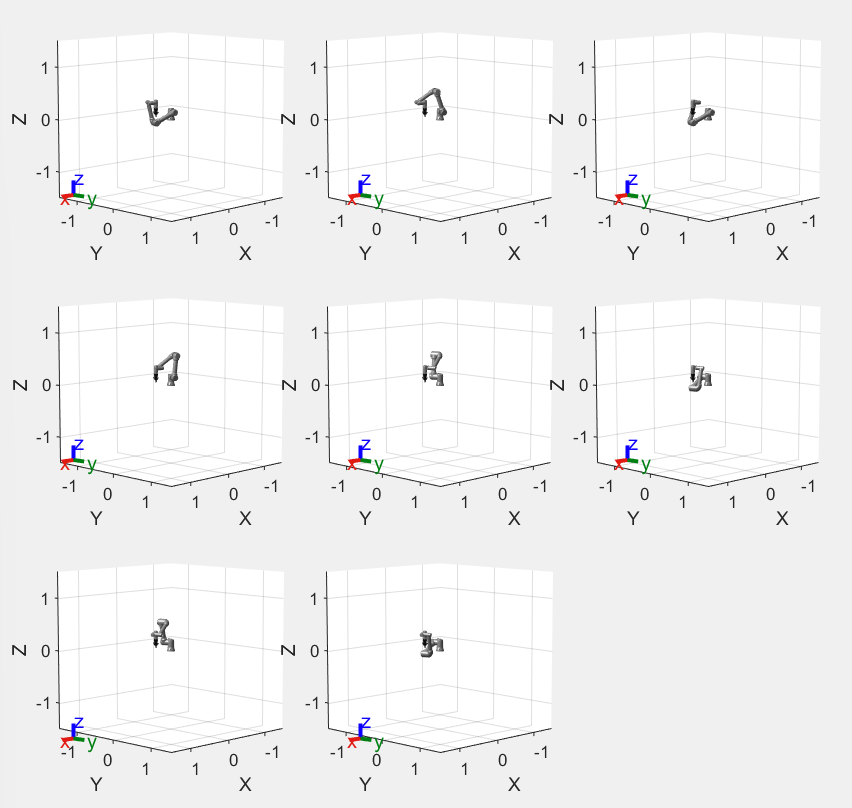

Fig. 8 Posibles soluciones del robot UR5e

Eliminamos las soluciones de mano hacia atrás

condicion = min(sum(CinematicaInversa.Muneca.^2,1)) - sum(CinematicaInversa.Muneca.^2,1) >= -0.0001

condicion = 1×8 logical array
   0   0   1   1   1   1   0   0


CinematicaInversa.Angulos = CinematicaInversa.Angulos(:,condicion);
CinematicaInversa.Codo = CinematicaInversa.Codo(condicion);
CinematicaInversa.Muneca = CinematicaInversa.Muneca(:,condicion);
display(CinematicaInversa)

CinematicaInversa = struct with fields:
    Angulos: [6×4 double]
       Codo: [4×1 double]
     Muneca: [3×4 double]



q = CinematicaInversa.Angulos

q =     2.8018    2.8018    0.3397    0.3397
    0.4291   -1.6779   -1.4637    2.7124
   -2.2816    2.2816   -2.2816    2.2816
    0.2817   -2.1745   -0.9670    2.8599
   -1.5708   -1.5708    1.5708    1.5708
   -1.9105   -1.9105   -1.2310   -1.2310


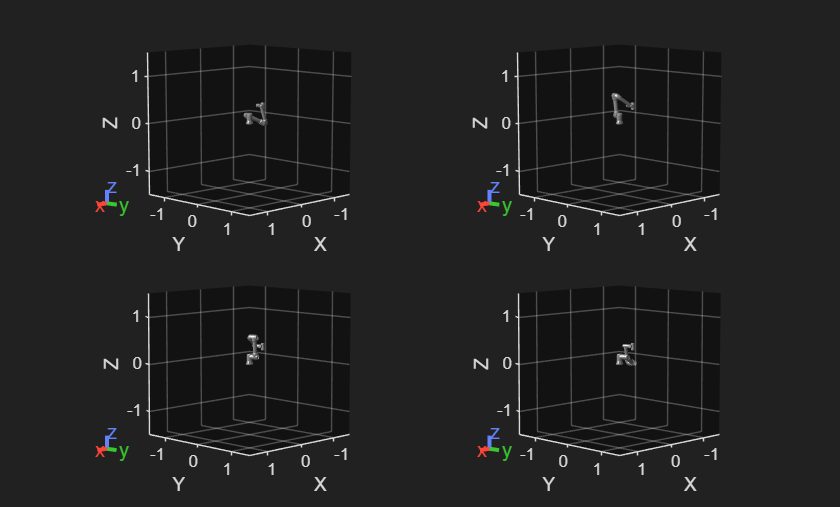

for m = 1:4
    for k = 1:6
        ConfiguracionRobot(k).JointPosition = q(k,m);
    end
    subplot(2,2,m)
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end

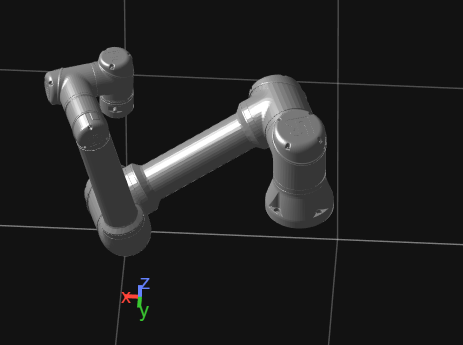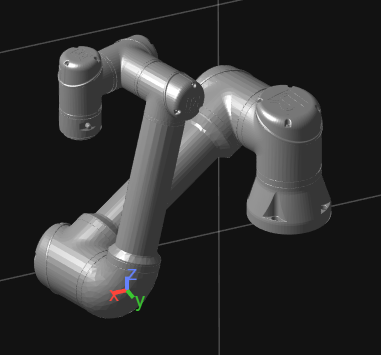

Fig. Muñeca hacia adelante y muñeca hacia atrás en el UR5e.

Nos quedamos con la solución codo para arriba. 

condicion = max(CinematicaInversa.Codo) - CinematicaInversa.Codo <= 0.0001;
CinematicaInversa.Angulos = CinematicaInversa.Angulos(:,condicion);
CinematicaInversa.Codo = CinematicaInversa.Codo(condicion);
CinematicaInversa.Muneca = CinematicaInversa.Muneca(:,condicion);
display(CinematicaInversa)

CinematicaInversa = struct with fields:
    Angulos: [6×2 double]
       Codo: [2×1 double]
     Muneca: [3×2 double]



q = CinematicaInversa.Angulos

q =     2.8018    0.3397
   -1.6779   -1.4637
    2.2816   -2.2816
   -2.1745   -0.9670
   -1.5708    1.5708
   -1.9105   -1.2310


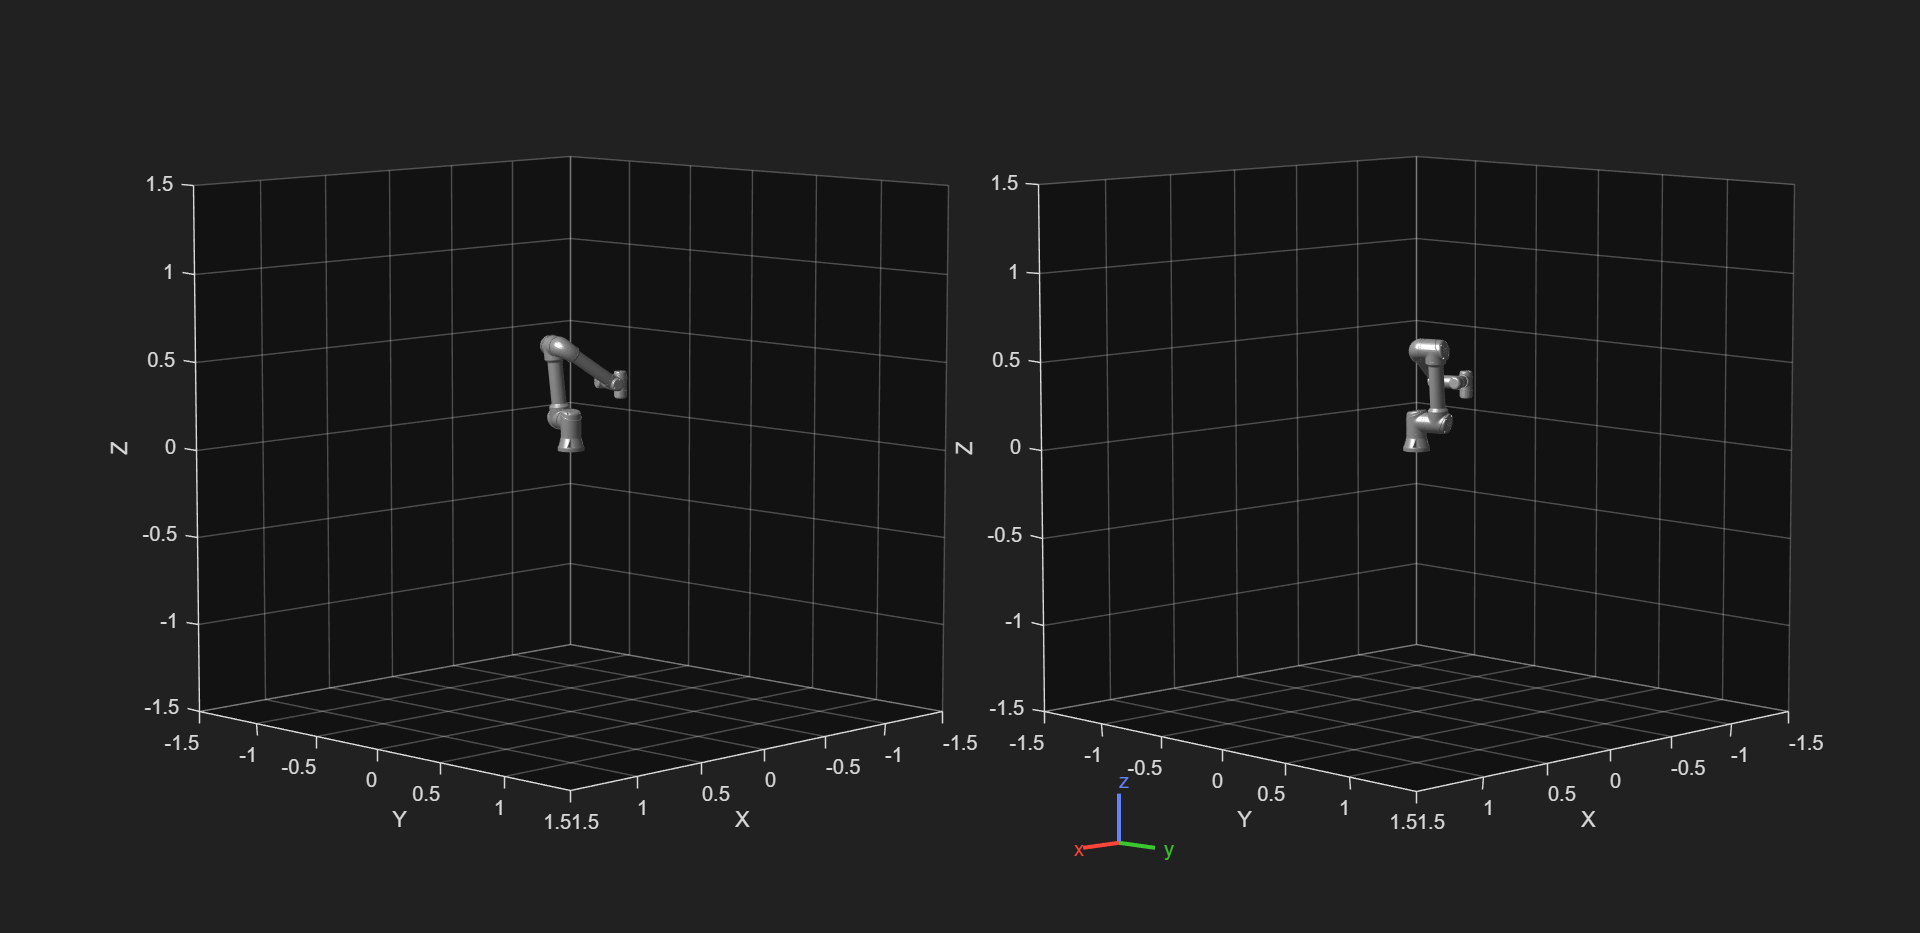

for m = 1:2
    for k = 1:6
        ConfiguracionRobot(k).JointPosition = q(k,m);
    end
    subplot(1,2,m)
    show(mi_ur5e,ConfiguracionRobot,Frames="off");
end

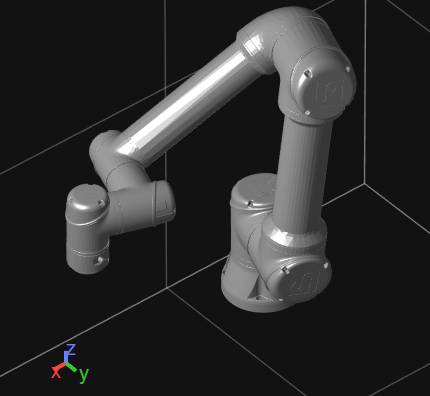

Fig. Codo hacia abajo, y codo hacia arriba en el UR5e.

Sin una estrategia condicional para diferenciar entre una posición "diestra" o "zurda". Simplemente dejamos que el robot escoja la primera, y las subsecuentes se quedan como las mas cercanas a esa posición.

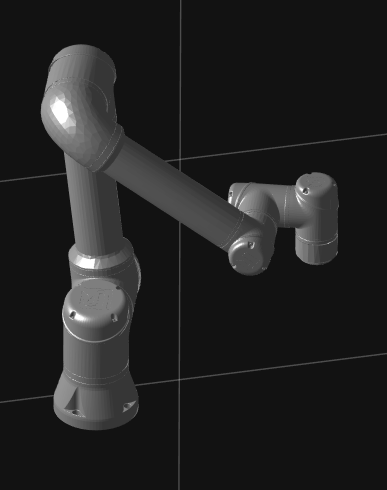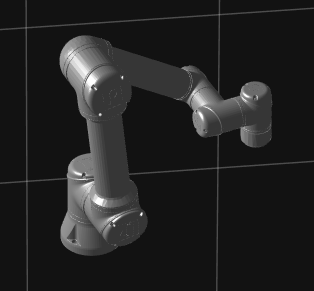

Fig. Robot zurdo o diestro.

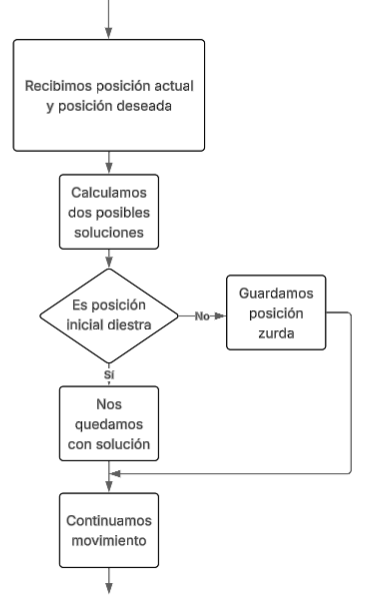

Fig. Diagrama de toma de decisión de robot zurdo o diestro.

## Movimiento de robot en trayectorias simples

Realicemos el movimiento del robot en un cuadrado dado por los vértices

$a^{\textrm{robot}} =\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 3\\
0\ldotp 1
\end{array}\right\rbrack$, $b^{\textrm{robot}} =\left\lbrack \begin{array}{c}
-0\ldotp 4\\
0\ldotp 3\\
0\ldotp 1
\end{array}\right\rbrack$, $c^{\textrm{robot}} =\left\lbrack \begin{array}{c}
-0\ldotp 4\\
0\ldotp 6\\
0\ldotp 1
\end{array}\right\rbrack$, y $d^{\textrm{robot}} =\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 6\\
0\ldotp 1
\end{array}\right\rbrack$,

### 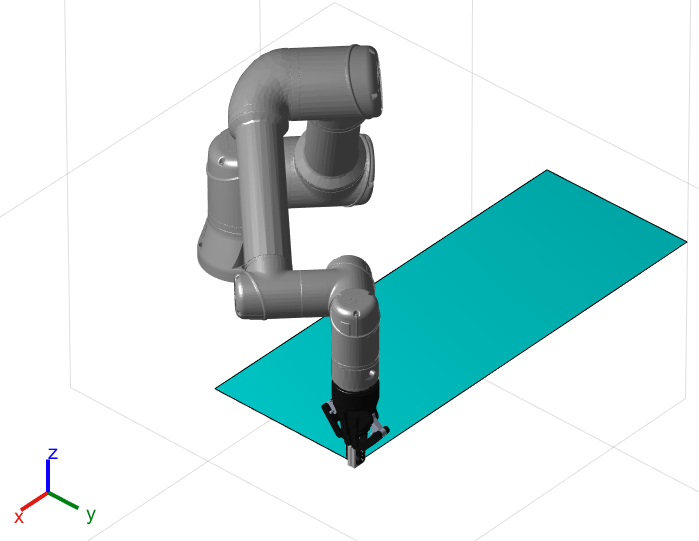

Fig. Robot tocando las 4 esquinas de un rectángulo

### Consideracionea al emplear la función inverseKinematics

Elapsed time is 0.664275 seconds.
Elapsed time is 0.564067 seconds.
Elapsed time is 0.032804 seconds.
Elapsed time is 0.397444 seconds.
Elapsed time is 0.081869 seconds.


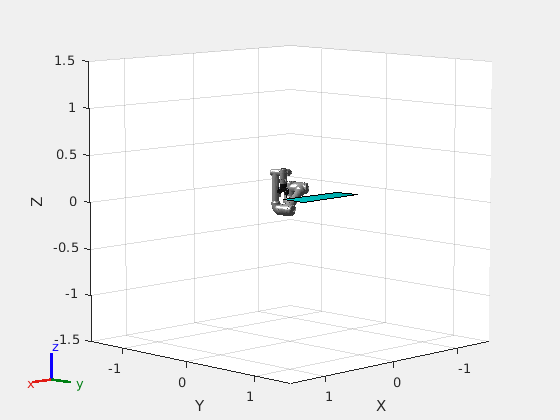

%Declaramos el robot con gripper
mi_ur5e = loadrobot("universalUR5e");
mi_gripper = loadrobot('robotiq2F85');
addSubtree(mi_ur5e, 'tool0', mi_gripper, ReplaceBase=false);


%Declaramos el solver de cinemática inversa
ik = inverseKinematics("RigidBodyTree",mi_ur5e);
weights = [1 1 1 1 1 1];
ConfiguracionRobot = homeConfiguration(mi_ur5e);

%Declaramos variables del robot y cuadrado
angles = [0 0 -pi];
cuadrado = [0.4 -0.4 -0.4 0.4 0.4;0.3 0.3 0.6 0.6 0.3;0.1 0.1 0.1 0.1 0.1];
vertices = cuadrado';


for m = 1:size(cuadrado,2)
    trvec = cuadrado(:,m);
    poseTF = se3(angles,"eul","ZYX",trvec');
    
    tform = poseTF.tform;
    punto_nuevo = tform(1:3,4)-0.168*tform(1:3,3);

    poseTF = se3(angles,"eul","ZYX",punto_nuevo');
    tic
    [ConfiguracionRobot,solnInfo] = ik("tool0",poseTF.tform,weights,ConfiguracionRobot);
    toc
    show(mi_ur5e,ConfiguracionRobot,Frames="off",PreservePlot=true);
    hold on
    fill3(vertices(:,1), vertices(:,2), vertices(:,3), 'cyan');
    hold off
    pause(0.1)
end

Empleando la función personalizada

Elapsed time is 0.002298 seconds.
Elapsed time is 0.008972 seconds.
Elapsed time is 0.038964 seconds.
Elapsed time is 0.025848 seconds.
Elapsed time is 0.007636 seconds.


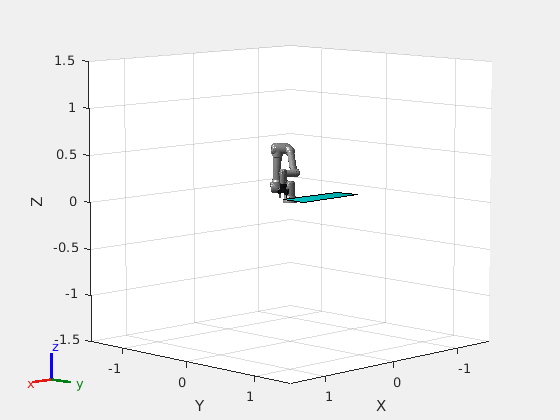

ConfiguracionRobot = homeConfiguration(mi_ur5e);

%Declaramos variables del robot y cuadrado
angles = [0 0 -pi];
cuadrado = [0.4 -0.4 -0.4 0.4 0.4;0.3 0.3 0.6 0.6 0.3;0.1 0.1 0.1 0.1 0.1];
vertices = cuadrado';
q = zeros(6,1);

for m = 1:size(cuadrado,2)
    trvec = cuadrado(:,m);
    poseTF = se3(angles,"eul","ZYX",trvec');
    tic
    CinematicaInversa = UnaSolucionesUR5e(poseTF.tform,q);
    toc
    q = CinematicaInversa.Angulos;
    q(1,:)=q(1,:)+pi; %Correción de parámetros.

    for k = 1:6
            ConfiguracionRobot(k).JointPosition = q(k,end);
    end

    show(mi_ur5e,ConfiguracionRobot,Frames="off",PreservePlot=true);
    hold on
    fill3(vertices(:,1), vertices(:,2), vertices(:,3), 'cyan');
    hold off
    pause(0.1)
end

## Práctica extra (Si el tiempo lo permite) Ajuste de puntos según el marco de referencia de la mesa

### ¿Qué ocurrirá si se modifican las coordenadas de la mesa de trabajo?

En este nuevo experimento se suguiere que los puntos estan en una mesa que:

a) Se desplaza,

b) Se rota,

c) Se desplaza y se rota

Se considera que la mesa tanto el robot comparten el marco de referencial inicial, los puntos que el robot debe visitar están anclados en la mesa y es está última la que translada y rota.

a) Si el origen de la mesa se translada, sin rotación, al nuevo punto

$p={\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 0\ldotp 2 & 0\ldotp 3
\end{array}\right\rbrack }^T$, la transformación homogenea entre el robot y la mesa, será


$$H_{\textrm{mesa}}^{\textrm{robot}} =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\ldotp 1\\
0 & 1 & 0 & 0\ldotp 1\\
0 & 0 & 1 & 0\ldotp 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Entonces, la representación de un punto en la mesa, visto desde el marco de referencia del robot, será


$$p^{\textrm{robot}} =H_{\textrm{mesa}}^{\textrm{robot}} p^{\textrm{mesa}}$$


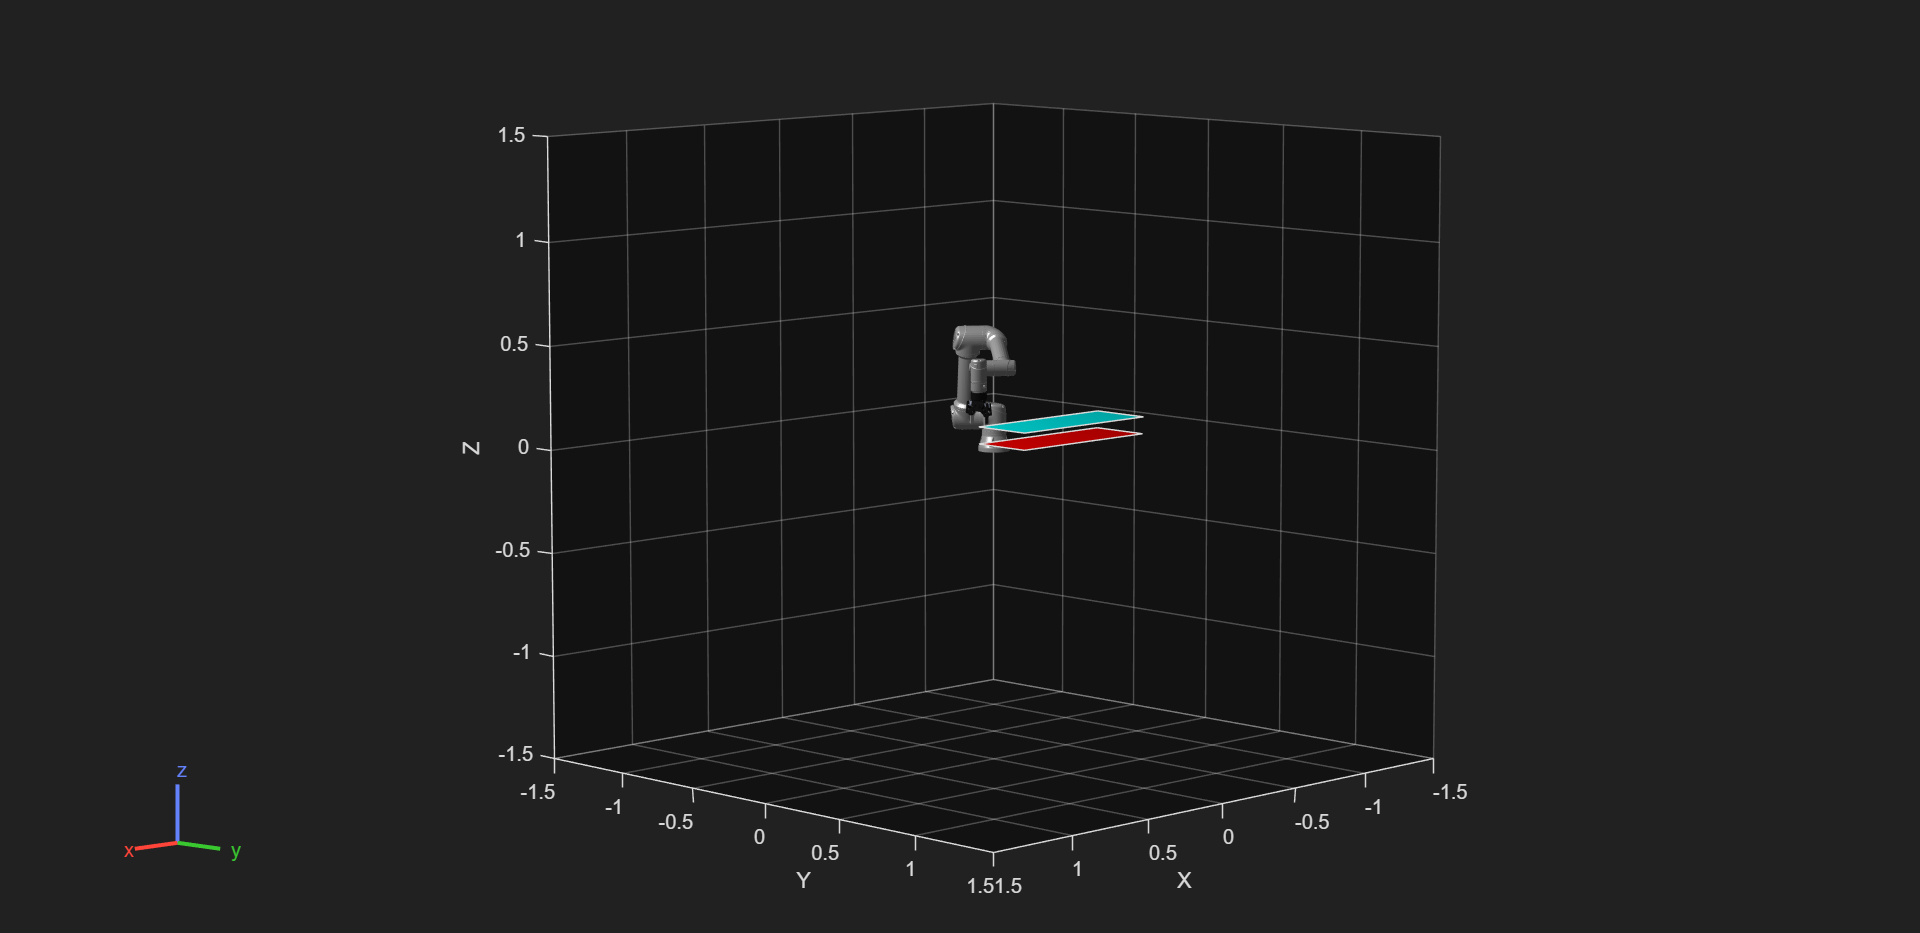

H_mesaRobot = [1 0 0 0.1;
               0 1 0 0.1;
               0 0 1 0.1;
               0 0 0 1.0];
angles = [0 0 -pi];
cuadrado = [0.4 -0.4 -0.4 0.4 0.4;0.3 0.3 0.6 0.6 0.3;0.1 0.1 0.1 0.1 0.1];
vertices = cuadrado';

nuevo_cuadrado = H_mesaRobot*[cuadrado;1 1 1 1 1];
nuevo_vertices = nuevo_cuadrado';

q=zeros(6,1);
for m = 1:size(nuevo_cuadrado,2)

    trvec = nuevo_cuadrado(1:3,m);
    poseTF = se3(angles,"eul","ZYX",trvec');

    CinematicaInversa = UnaSolucionesUR5e(poseTF.tform,q);
    q = CinematicaInversa.Angulos;

    q(1,:)=q(1,:)+pi; %Correción de parámetros.

    for k = 1:6
            ConfiguracionRobot(k).JointPosition = q(k);
    end

    show(mi_ur5e,ConfiguracionRobot,Frames="off",PreservePlot=true);
    hold on
    fill3(vertices(:,1), vertices(:,2), vertices(:,3), 'red');
    fill3(nuevo_vertices(:,1), nuevo_vertices(:,2), nuevo_vertices(:,3), 'cyan');
    hold off
    pause(0.05)
end

b) Si se considera una rotación de $\theta$ grados de la mesa alrededor del eje $y$, sin tranlación, la transformación homogenea entre el robot y la mesa, será el producto 


$$H_{\textrm{mesa}}^{\textrm{robot}} =\left\lbrack \begin{array}{cccc}
\cos \;\theta  & 0 & \sin \;\theta  & 0\\
0 & 1 & 0 & 0\\
-\sin \;\theta  & 0 & \cos \;\theta  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Entonces, la representación de un punto en la mesa, visto desde el marco de referencia del robot, será


$$p^{\textrm{robot}} =H_{\textrm{mesa}}^{\textrm{robot}} p^{\textrm{mesa}}$$


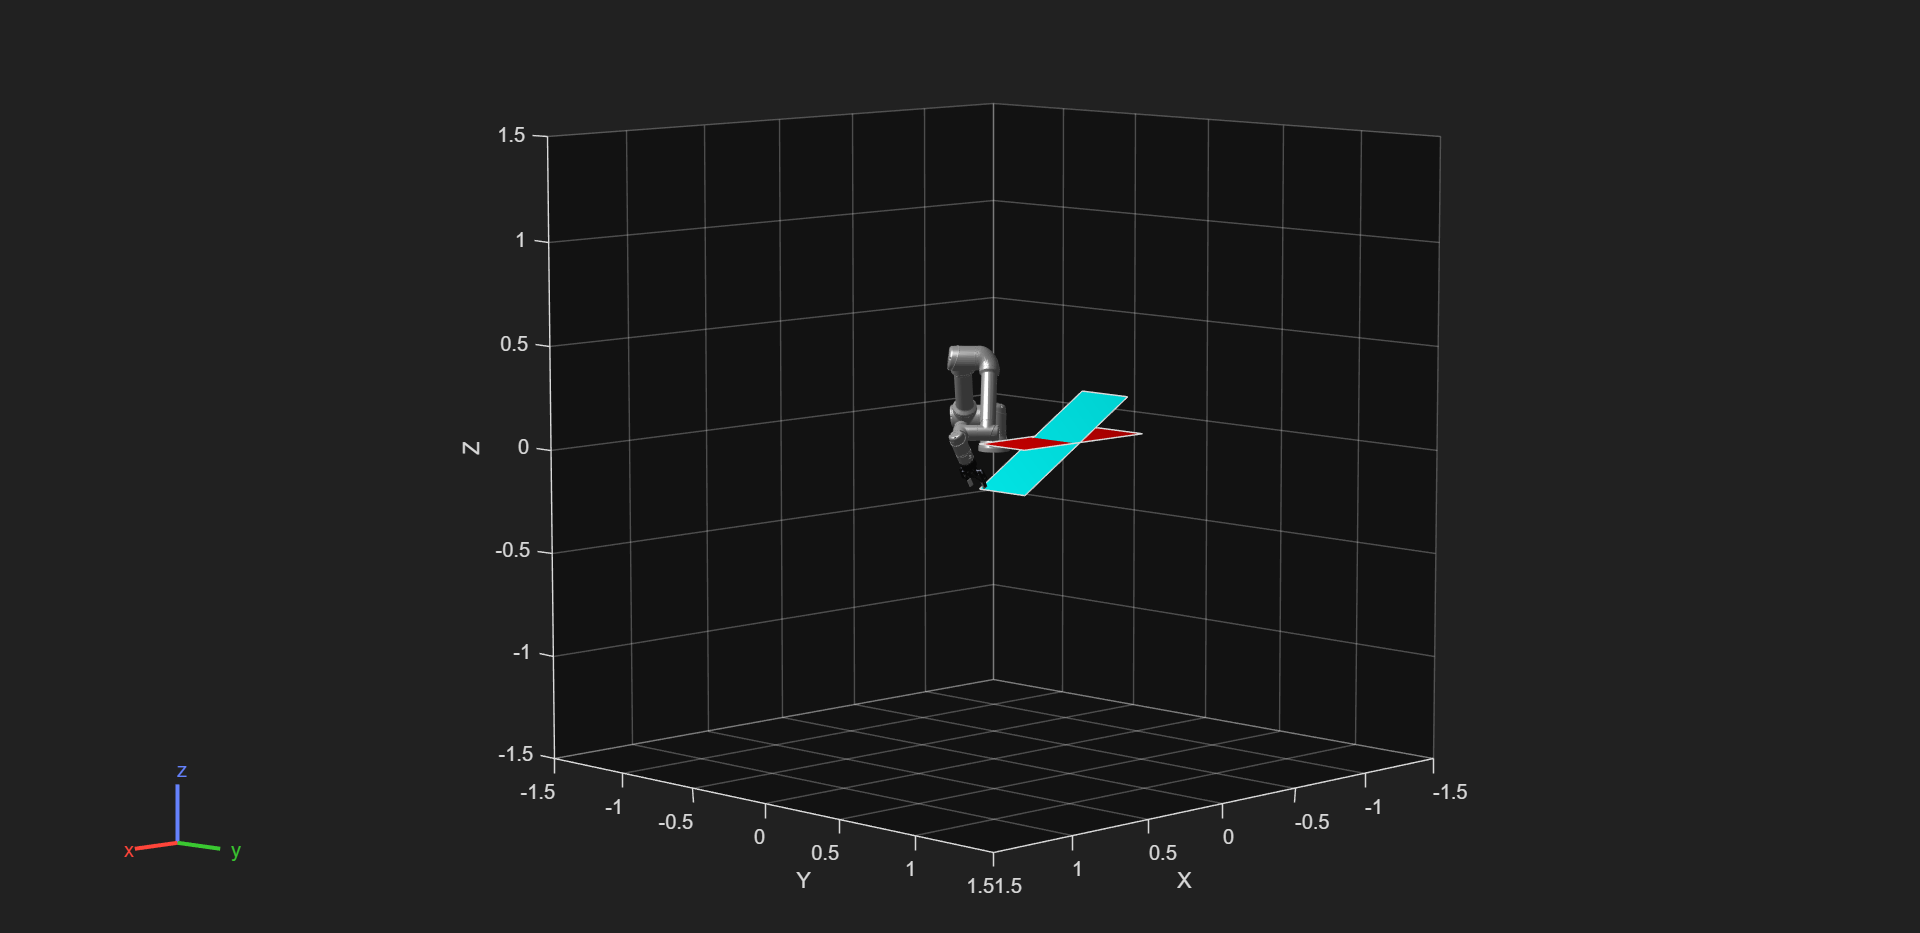

theta = pi/6;
H_mesaRobot = [ cos(theta) 0 sin(theta) 0;
                0          1 0          0
               -sin(theta) 0 cos(theta) 0;
               0           0 0          1.0];

angles = [0 0 -pi];
cuadrado = [0.4 -0.4 -0.4 0.4 0.4;0.3 0.3 0.6 0.6 0.3;0.1 0.1 0.1 0.1 0.1];
vertices = cuadrado';

nuevo_cuadrado = H_mesaRobot*[cuadrado;1 1 1 1 1];
nuevo_vertices = nuevo_cuadrado';

q=zeros(6,1);

for m = 1:size(nuevo_cuadrado,2)
    trvec = cuadrado(1:3,m);
    poseTF = se3(angles,"eul","ZYX",trvec');

    tforma = poseTF.tform;
    nueva_pose = H_mesaRobot*tforma;

    CinematicaInversa = UnaSolucionesUR5e(nueva_pose,q);
    q = CinematicaInversa.Angulos;

    q(1,:)=q(1,:)+pi; %Correción de parámetros.

    for k = 1:6
            ConfiguracionRobot(k).JointPosition = q(k);
    end

    show(mi_ur5e,ConfiguracionRobot,Frames="off",PreservePlot=true);
    hold on
    fill3(vertices(:,1), vertices(:,2), vertices(:,3), 'red');
    fill3(nuevo_vertices(:,1), nuevo_vertices(:,2), nuevo_vertices(:,3), 'cyan');
    hold off
    pause(0.05)
end

c) Si se considera una rotación seguido de una translación, la transformación homogenea entre el robot y la mesa, será


$$H_{\textrm{mesa}}^{\textrm{robot}} =\left\lbrack \begin{array}{cccc}
\cos \;\theta  & 0 & \sin \;\theta  & 0\\
0 & 1 & 0 & 0\\
-\sin \;\theta  & 0 & \cos \;\theta  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\ldotp 1\\
0 & 1 & 0 & -0\ldotp 1\\
0 & 0 & 1 & 0\ldotp 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


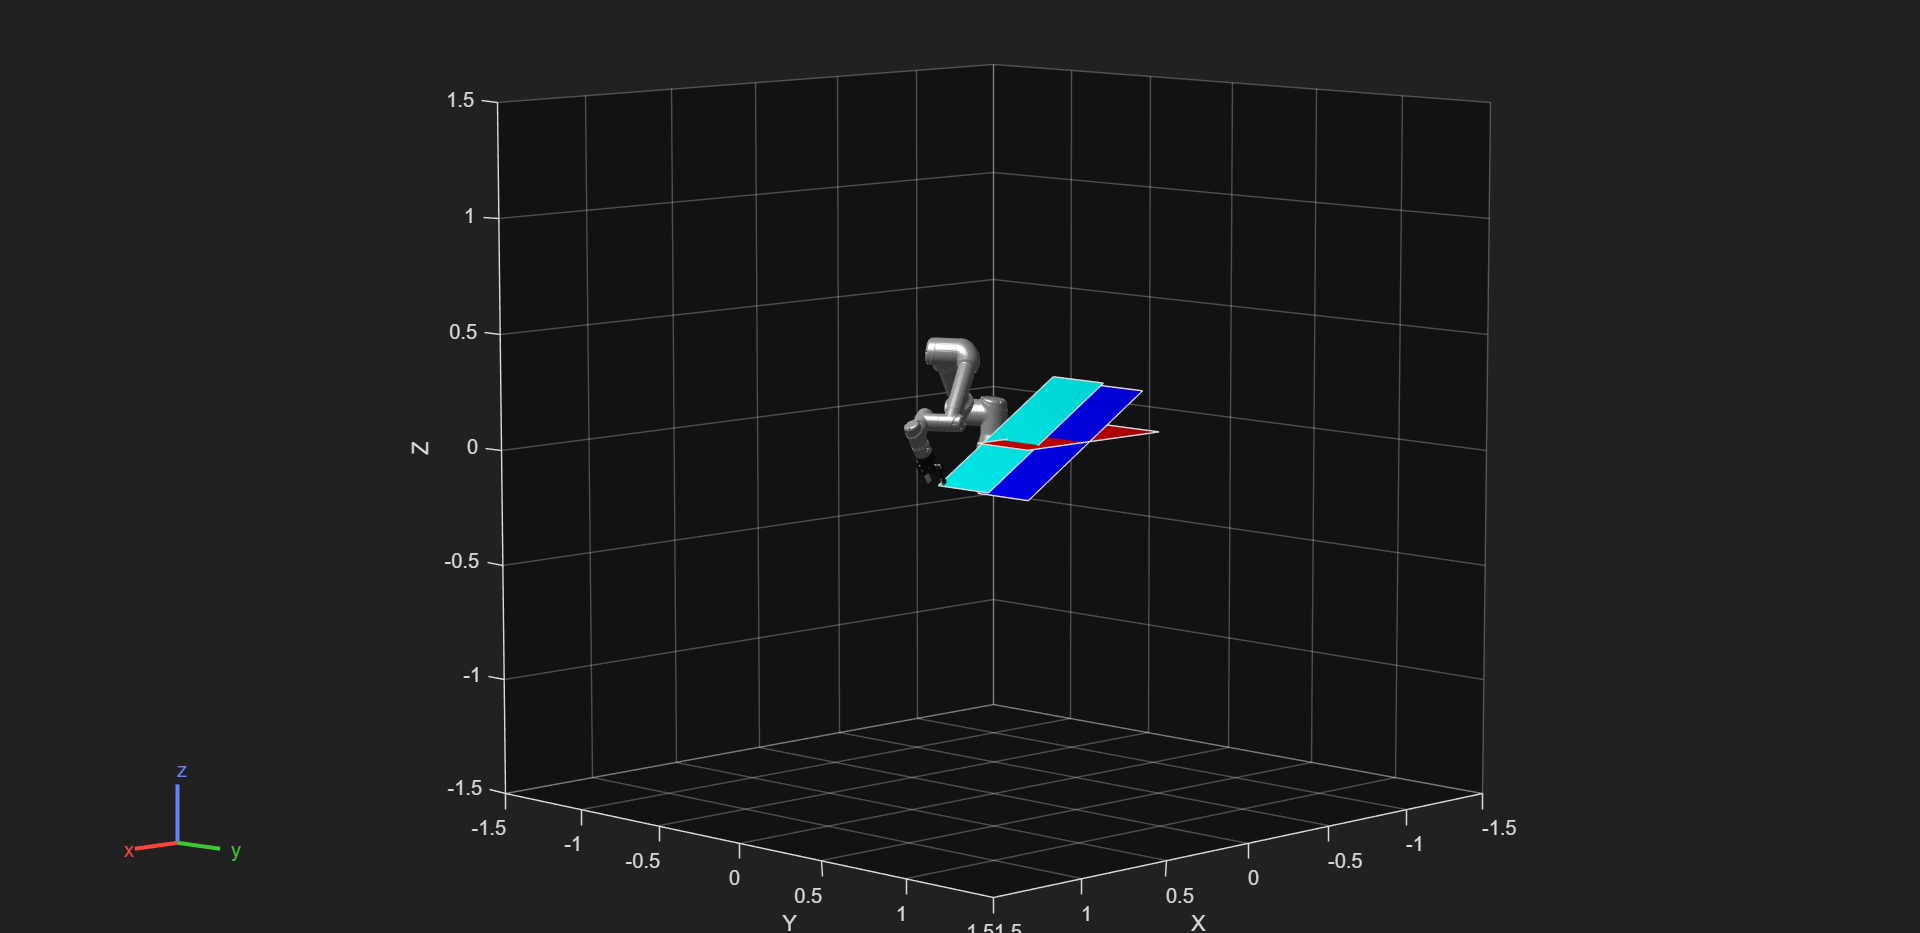

theta = pi/6;
H_1 = [ cos(theta) 0 sin(theta) 0;
                0          1 0          0
               -sin(theta) 0 cos(theta) 0;
               0           0 0          1.0];

H_2 = [1 0 0 0.1;
       0 1 0 -0.1;
       0 0 1 0.1;
       0 0 0 1.0];

H_mesaRobot = H_1 * H_2;

tic
angles = [0 0 -pi];
cuadrado = [0.4 -0.4 -0.4 0.4 0.4;0.3 0.3 0.6 0.6 0.3;0.1 0.1 0.1 0.1 0.1];
vertices = cuadrado';

cuadrado_1 = H_1 *[cuadrado;1 1 1 1 1];
vertices_1 = cuadrado_1';
cuadrado_2 = H_1*H_2*[cuadrado;1 1 1 1 1];
vertices_2 = cuadrado_2';

q=zeros(6,1);

for m = 1:size(nuevo_cuadrado,2)
    trvec = cuadrado(1:3,m);
    poseTF = se3(angles,"eul","ZYX",trvec');

    tforma = poseTF.tform;

    nueva_pose = H_1*H_2*tforma;

    CinematicaInversa = UnaSolucionesUR5e(nueva_pose,q);
    q = CinematicaInversa.Angulos;

    q(1,:)=q(1,:)+pi; %Correción de parámetros.

    for k = 1:6
            ConfiguracionRobot(k).JointPosition = q(k);
    end

    show(mi_ur5e,ConfiguracionRobot,Frames="off",PreservePlot=true);
    hold on
    fill3(vertices(:,1), vertices(:,2), vertices(:,3), 'red');
    fill3(vertices_1(:,1), vertices_1(:,2), vertices_1(:,3), 'blue');
    fill3(vertices_2(:,1), vertices_2(:,2), vertices_2(:,3), 'cyan');
    hold off
    pause(0.05)
end

toc

Elapsed time is 7.806964 seconds.


# Apéndice

## Funciones adicionales

### Función para graficar vectores

Esta función fue generada en CHAT-GPT con el promt: 

"Realiza una función que grafique 3 vectores en Matlab usando la transformación homogénea. Considera como punto de partida el punto 3D de la función homogénea. "

function graficar_vectores(T)
% GRAFICAR_VECTORES Grafica 3 vectores (x, y, z) desde el punto de partida definido en T.
% Entrada:
%   T - matriz de transformación homogénea 4x4

    % Validar matriz homogénea
    if ~isequal(size(T), [4 4])
        error('La matriz de transformación homogénea debe ser de tamaño 4x4.');
    end

    % Obtener origen desde T
    origen = T(1:3, 4);

    % Obtener los vectores unitarios transformados (columnas de R)
    x_vec = T(1:3, 1);  % eje X
    y_vec = T(1:3, 2);  % eje Y
    z_vec = T(1:3, 3);  % eje Z

    % Longitud de vectores para visualización
    L = 1;

    % Crear figura
    hold on;

    %Imprimimos punto
    plot3(origen(1),origen(2),origen(3),MarkerSize=10,Marker="o",MarkerFaceColor='b')
    
    % Dibujar vectores desde el punto origen
    quiver3(origen(1), origen(2), origen(3), L*x_vec(1), L*x_vec(2), L*x_vec(3), 0, 'r', 'LineWidth', 2); % X
    quiver3(origen(1), origen(2), origen(3), L*y_vec(1), L*y_vec(2), L*y_vec(3), 0, 'g', 'LineWidth', 2); % Y
    quiver3(origen(1), origen(2), origen(3), L*z_vec(1), L*z_vec(2), L*z_vec(3), 0, 'b', 'LineWidth', 2); % Z

    hold off
end

Promt: Graficar una esfera hueca 3d de radio 0.85 en Matlab. Colocalo dentro de una función.

function graficarEsferaHueca(r)
    % GRAFICARESPHERAHUECA Dibuja una esfera hueca 3D de radio r
    %
    % Uso:
    %   graficarEsferaHueca(0.85)

    % Generar malla esférica
    [theta, phi] = meshgrid(linspace(0, pi, 50), linspace(0, 2*pi, 50));

    % Convertir a coordenadas cartesianas
    x = r * sin(theta) .* cos(phi);
    y = r * sin(theta) .* sin(phi);
    z = r * cos(theta)+0.089159;

    % Graficar superficie
    h = surf(x, y, z);

    % Configuración de la transparencia y estilo
    h.FaceAlpha = 0.1;      % Caras muy transparentes
    h.EdgeColor = 'k';      % Frame en color negro
    h.FaceColor = 'interp'; % Color interpolado para el frame
end


Hacemos del desplazamiento lineal una función

% %Solución GPT
% % Suponemos que ya tienes tu robot cargado como "mi_ur5e"
% % Y que ya se definieron las configuraciones inicial y final
% function movimientoLineal(robot,Posicion1,Posicion2,N)
%     % Posicion1 = mi_ur5e.randomConfiguration;
%     % Posicion2 = mi_ur5e.randomConfiguration;
% 
%     % Convertimos las configuraciones a vectores de ángulos articulares
%     q1 = [Posicion1.JointPosition];
%     q2 = [Posicion2.JointPosition];
% 
%     % Número de pasos para la interpolación
%     % N = 50;
% 
%     % Prealocamos el arreglo para guardar las trayectorias
%     traj = zeros(N, length(q1));
% 
%     % Interpolamos línea por línea (espacio articular)
%     for i = 1:N
%         alpha = (i - 1)/(N - 1); % Factor de interpolación de 0 a 1
%         traj(i, :) = (1 - alpha) * q1 + alpha * q2;
%     end
% 
%     % Visualización de la trayectoria
%     figure;
%     for i = 1:N
%         config = homeConfiguration(robot);
%         for j = 1:length(config)
%             config(j).JointPosition = traj(i, j);
%         end
%         show(robot, config, 'PreservePlot', false, 'Frames', 'off');
%         view(150,90)
%         title(['Paso ', num2str(i)]);
%         drawnow;
% 
%     end
% end


Código corregido con el prompt

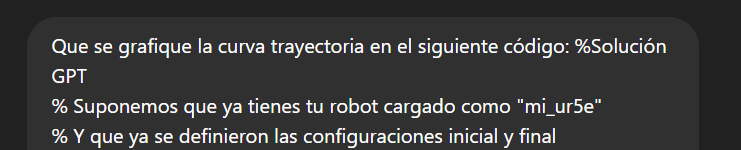

function movimientoLineal(robot, Posicion1, Posicion2, N)
    % Convertimos las configuraciones a vectores de ángulos articulares
    q1 = [Posicion1.JointPosition];
    q2 = [Posicion2.JointPosition];

    % Prealocamos el arreglo para guardar las trayectorias
    traj = zeros(N, length(q1));
    posicionesEfector = zeros(N, 3); % Para guardar las posiciones XYZ del efector final

    % Interpolamos línea por línea (espacio articular)
    for i = 1:N
        alpha = (i - 1) / (N - 1); % Factor de interpolación
        traj(i, :) = (1 - alpha) * q1 + alpha * q2;
    end

    % Crear figura
    figure;
    grid on;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Trayectoria del efector final');

    % Mostrar el robot y guardar las posiciones del efector
    for i = 1:N
        config = homeConfiguration(robot);
        for j = 1:length(config)
            config(j).JointPosition = traj(i, j);
        end

        % Obtener posición del efector final
        tform = getTransform(robot, config, robot.BodyNames{end});
        posicionesEfector(i, :) = tform(1:3, 4)';

        % Mostrar robot
        show(robot, config, 'PreservePlot', false, 'Frames', 'off');
        view(150,90)
        hold on;
        plot3(posicionesEfector(1:i, 1), posicionesEfector(1:i, 2), posicionesEfector(1:i, 3), 'r-', 'LineWidth', 2);
        drawnow;
    end
end
